# 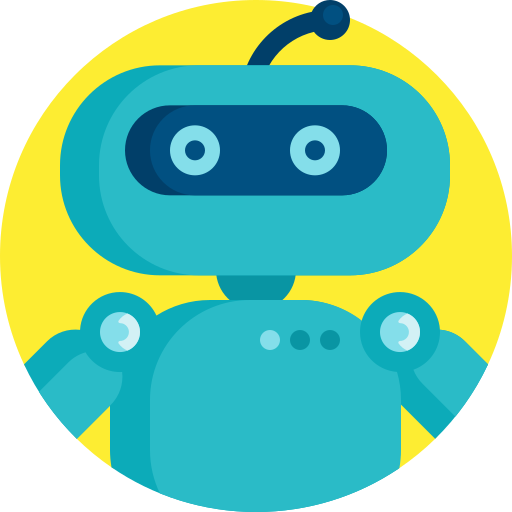

# **MEC4127F: Introduction to Robotics**

# Chapter 3: Describing pose

## 3.1 Introduction

This chapter will largely focus on the interrelation between angular velocity and orientation of different representations. The latter part of this chapter will then develop an exact mapping that can be used to relate pose-rate information (translational and rotational velocity) to pose.

Based on our results in **Chapter 2**, we now have a means of encoding the orientation of our robot body with respect to a reference frame of interest. The rotation matrix, $\bf R$, is a useful starting point in containing orientation and also plays a pivotal role in mapping vectors between frames. However, our prior knowledge of mathematics means that we are probably more comfortable with visualising rotations using individual angles. In fact, while the rotation matrix requires 9 elements to be fully populated based on the direction cosine formulation of 


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right] = \left[\begin{array}{cccccccc}    \cos(\alpha_{xx}) & \cos(\alpha_{yx}) & \cos(\alpha_{zx}) \\    \cos(\alpha_{xy}) & \cos(\alpha_{yy}) & \cos(\alpha_{zy}) \\    \cos(\alpha_{xz}) & \cos(\alpha_{yz}) & \cos(\alpha_{zz})    \\ \end{array}\right]=
\left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]
,\ \end{array}$$


we actually only need to know as little as $3$ distinct values to define the orientation. This follows from the fact that an orthogonal matrix imposes $6$ constraints on the $9$-element matrix $\bf R$; $3$ from the unit-norm requirement of 


$$\begin{array}{cc}r_{11}^2+r_{21}^2+r_{31}^2=1,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{12}^2+r_{22}^2+r_{32}^2=1,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{13}^2+r_{23}^2+r_{33}^2=1,\\ \end{array}$$


and $3$ from the orthogonality condition of 


$$\begin{array}{cc}r_{11}r_{12}+r_{21}r_{22}+r_{31}r_{32}=0,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{12}r_{13}+r_{22}r_{23}+r_{32}r_{33}=0,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{11}r_{13}+r_{21}r_{23}+r_{31}r_{33}=0.\\ \end{array}$$


With $9$ unknown terms in $\bf R$ and $6$ constraints, this results in $3$ free parameters. This result should not be terribly surprising considering that we are working in a three-dimensional space with three axes. 

Note that in the special case of planar rotation, as discussed in **Section 2.3.3**, the orientation corresponding to the rotation matrix 


$$\begin{array}{ll}
{\mathbf R} 
= \left[\begin{array}{cc}    {\cos\theta & -\sin\theta \\     \sin\theta & \cos\theta    \\ \end{array}\right],
\end{array}$$


is uniquely described by the single angle $\theta$. 

### 3.1.1 Representing orientation

There are a number of different ways to represent orientation. While rotation matrices have their uses in performing vector or frame mappings, it is not always obvious what orientation is being described within the $3\times3$ matrix form. Additionally, when visualising orientation on a time-domain plot, for example to assess the attitude of a spacecraft, vector descriptions of orientation make more sense. We will also see later in this course that vector-based orientation descriptors fit better in state estimation and control design techniques.

We will consider four main methods of representing orientation (directly or indirectly) in this course:

- Rotation matrices

- Euler angles

- Quaternions

- Exponential coordinates

Notably, each of these approaches has relative strengths and weaknesses. We will see later in this Chapter that Euler angles and exponential coordinates are a useful means of *directly* describing orientation, whereas quaternions and rotation matrices *indirectly *describe orientation and are ways to encode orientation in a functional way to facilitate vector or frame mappings.

## 3.2 Euler angles 

**Euler angles** are arguably the most common representation used when describing orientation in robotics and can be used to encode/decode orientation information from the rotation matrix. In the case of capturing the frame $\{B\}$ orientation with respect to $\{W\}$, the Euler angle vector is given by


$$\begin{array}{cc}{^W\mathbf\eta_B} = \left[\begin{array}{cc}    \phi \\    \theta \\    \psi    \\ \end{array}\right],\\ \end{array}$$


which uniquely describes the relative orientation using three angles:

- roll ($\phi$), 

- pitch ($\theta$), 

- yaw ($\psi$).

These three angles have the following bounds: 

- $\{\phi,\psi\}\in[-\pi,\pi]$, 

- $\theta\in[-\frac{\pi}{2},\frac{\pi}{2}]$.

Euler angles describe a particular orientation using three disparate rotations. The basic concept is that we can construct the orientation of one reference frame relative to another by using three sequential, distinct rotations about the principal axes of one of the frames. 

### 3.2.1 Rotation sequence

In the case of the single rigid-body problem, and using our two frames of interest, $\{W\}$ and $\{B\}$, we are going to make three sequential rotations about our *current* reference frame, moving "backwards" from frame $\{W\}$, eventually to frame $\{B\}$. We begin in frame $\{W\}$with a null rotation matrix of  $\mathbf R = {\bf I}$ (our current reference frame that is attached to the robot body and $\{W\}$ are aligned). With reference to Figure 3.1, we start by first rotating about the current $z$ -axis,  $\hat{\mathbf z}_W$ , with angle $\psi$ (shown in the leftmost image).

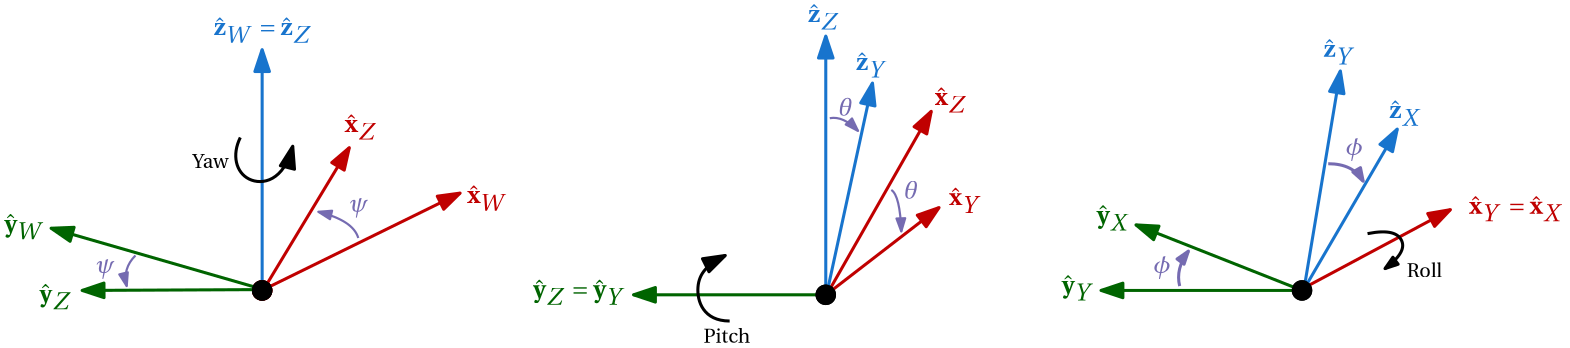

**Figure 3.1:** Intrinsic Euler ZYX rotation sequence. 
 

The rotation matrix that corresponds to this rotation about  $\hat{\mathbf z}_W$, rotating from $\{W\}$ to the new frame $\{Z\}$, is 


$$\begin{array}{cc}^W{\mathbf R}_Z = \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


$^W{\mathbf R}_Z$ is known as an elementary rotation and notably only affects vectors in the  $\hat{\mathbf x}_W$ - $\hat{\mathbf y}_W$ plane (the  $z$ component is unaffected). Note that we have implicitly introduced a new reference frame, $\{Z\}$, from this rotation, with the above equation describing the orientation of $\{Z\}$ relative to $\{W\}$. Following this, we then rotate about the $y$-axis of $\{Z\}$,  $\hat{\bf y}_Z$, with angle $\theta$. The incremental rotation matrix that rotates $\{Z\}$ to $\{Y\}$ is


$$\begin{array}{cc}^Z{\mathbf R}_Y = \left[\begin{array}{cccccccc}    \cos{\theta} & 0 & \sin{\theta} \\    0 & 1 & 0 \\    -\sin{\theta} & 0 & \cos{\theta}    \\ \end{array}\right].\\ \end{array}$$


We have again introduced a new reference frame, $\{Y\}$, using an elementary rotation. The final step is to rotate about  $\hat{\mathbf x}_Y$ with angle $\phi$. The corresponding incremental rotational mapping from $\{Y\}$ to $\{X\}=\{B\}$ (our body-frame of interest) is


$$\begin{array}{cc}^Y{\mathbf R}_B = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\phi} & -\sin{\phi} \\    0 & \sin{\phi} & \cos{\phi}    \\ \end{array}\right].\\ \end{array}$$


We can now stitch together the sequential rotations (keeping an eye on the subscripts and superscripts to aid the multiplication order) to describe our body-frame orientation, relative to the world frame: 


$$\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}.\\ \end{array}$$


This representation makes use of *Z-Y-X Euler angles, *with the"Z-Y-X" term indicating the rotation order. The rotation sequence that we have just followed can be thought of as so-called *intrinsic,* as the three rotations are performed around one of the "new" reference frame principal axes. *Extrinsic Euler angles* by contrast result from performing three rotations about different combinations of the world-frame axes. 

The form derived above is commonly referred to as *Tait-Bryan Angles*, or *nautical* *angles*. That is, we first rotated about  $\hat{\mathbf z}_W$ , followed by a rotation about  $\hat{\mathbf y}_Z$ , and finishing with a rotation about  $\hat{\mathbf x}_Y$ . Explicitly, our rotation matrix, parameterised by the Z-Y-X Euler angles, is written as


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right]    \left[\begin{array}{cccccccc}    \cos{\theta} & 0 & \sin{\theta} \\    0 & 1 & 0 \\    -\sin{\theta} & 0 & \cos{\theta}    \\ \end{array}\right]    \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\phi} & -\sin{\phi} \\    0 & \sin{\phi} & \cos{\phi}    \\ \end{array}\right], \end{array}$$


and after performing the matrix multiplication yields 


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    .\end{array}$$


syms phi alpha psi real

Rz = [cos(psi) -sin(psi) 0;
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(alpha)   0   sin(alpha);
      0          1       0;
     -sin(alpha)   0   cos(alpha)];
Rx = [1     0        0;
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];

R = Rz*Ry*Rx

$$R = \left(\begin{array}{ccc} \cos\left(\alpha \right)\,\cos\left(\psi \right) & \cos\left(\psi \right)\,\sin\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\alpha \right)\\ \cos\left(\alpha \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\alpha \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\sin\left(\alpha \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right)\,\sin\left(\varphi \right) & \cos\left(\alpha \right)\,\cos\left(\varphi \right) \end{array}\right)$$

While the matrix above may seem a bit overwhelming, it is important to note that we only require three variables to fully define it, namely the Euler angles - $\{ \phi, \theta, \psi \}$ , which respectively describe roll, pitch, and yaw — see Figure 3.2 for a useful mnemonic to remember the rotation axes. 

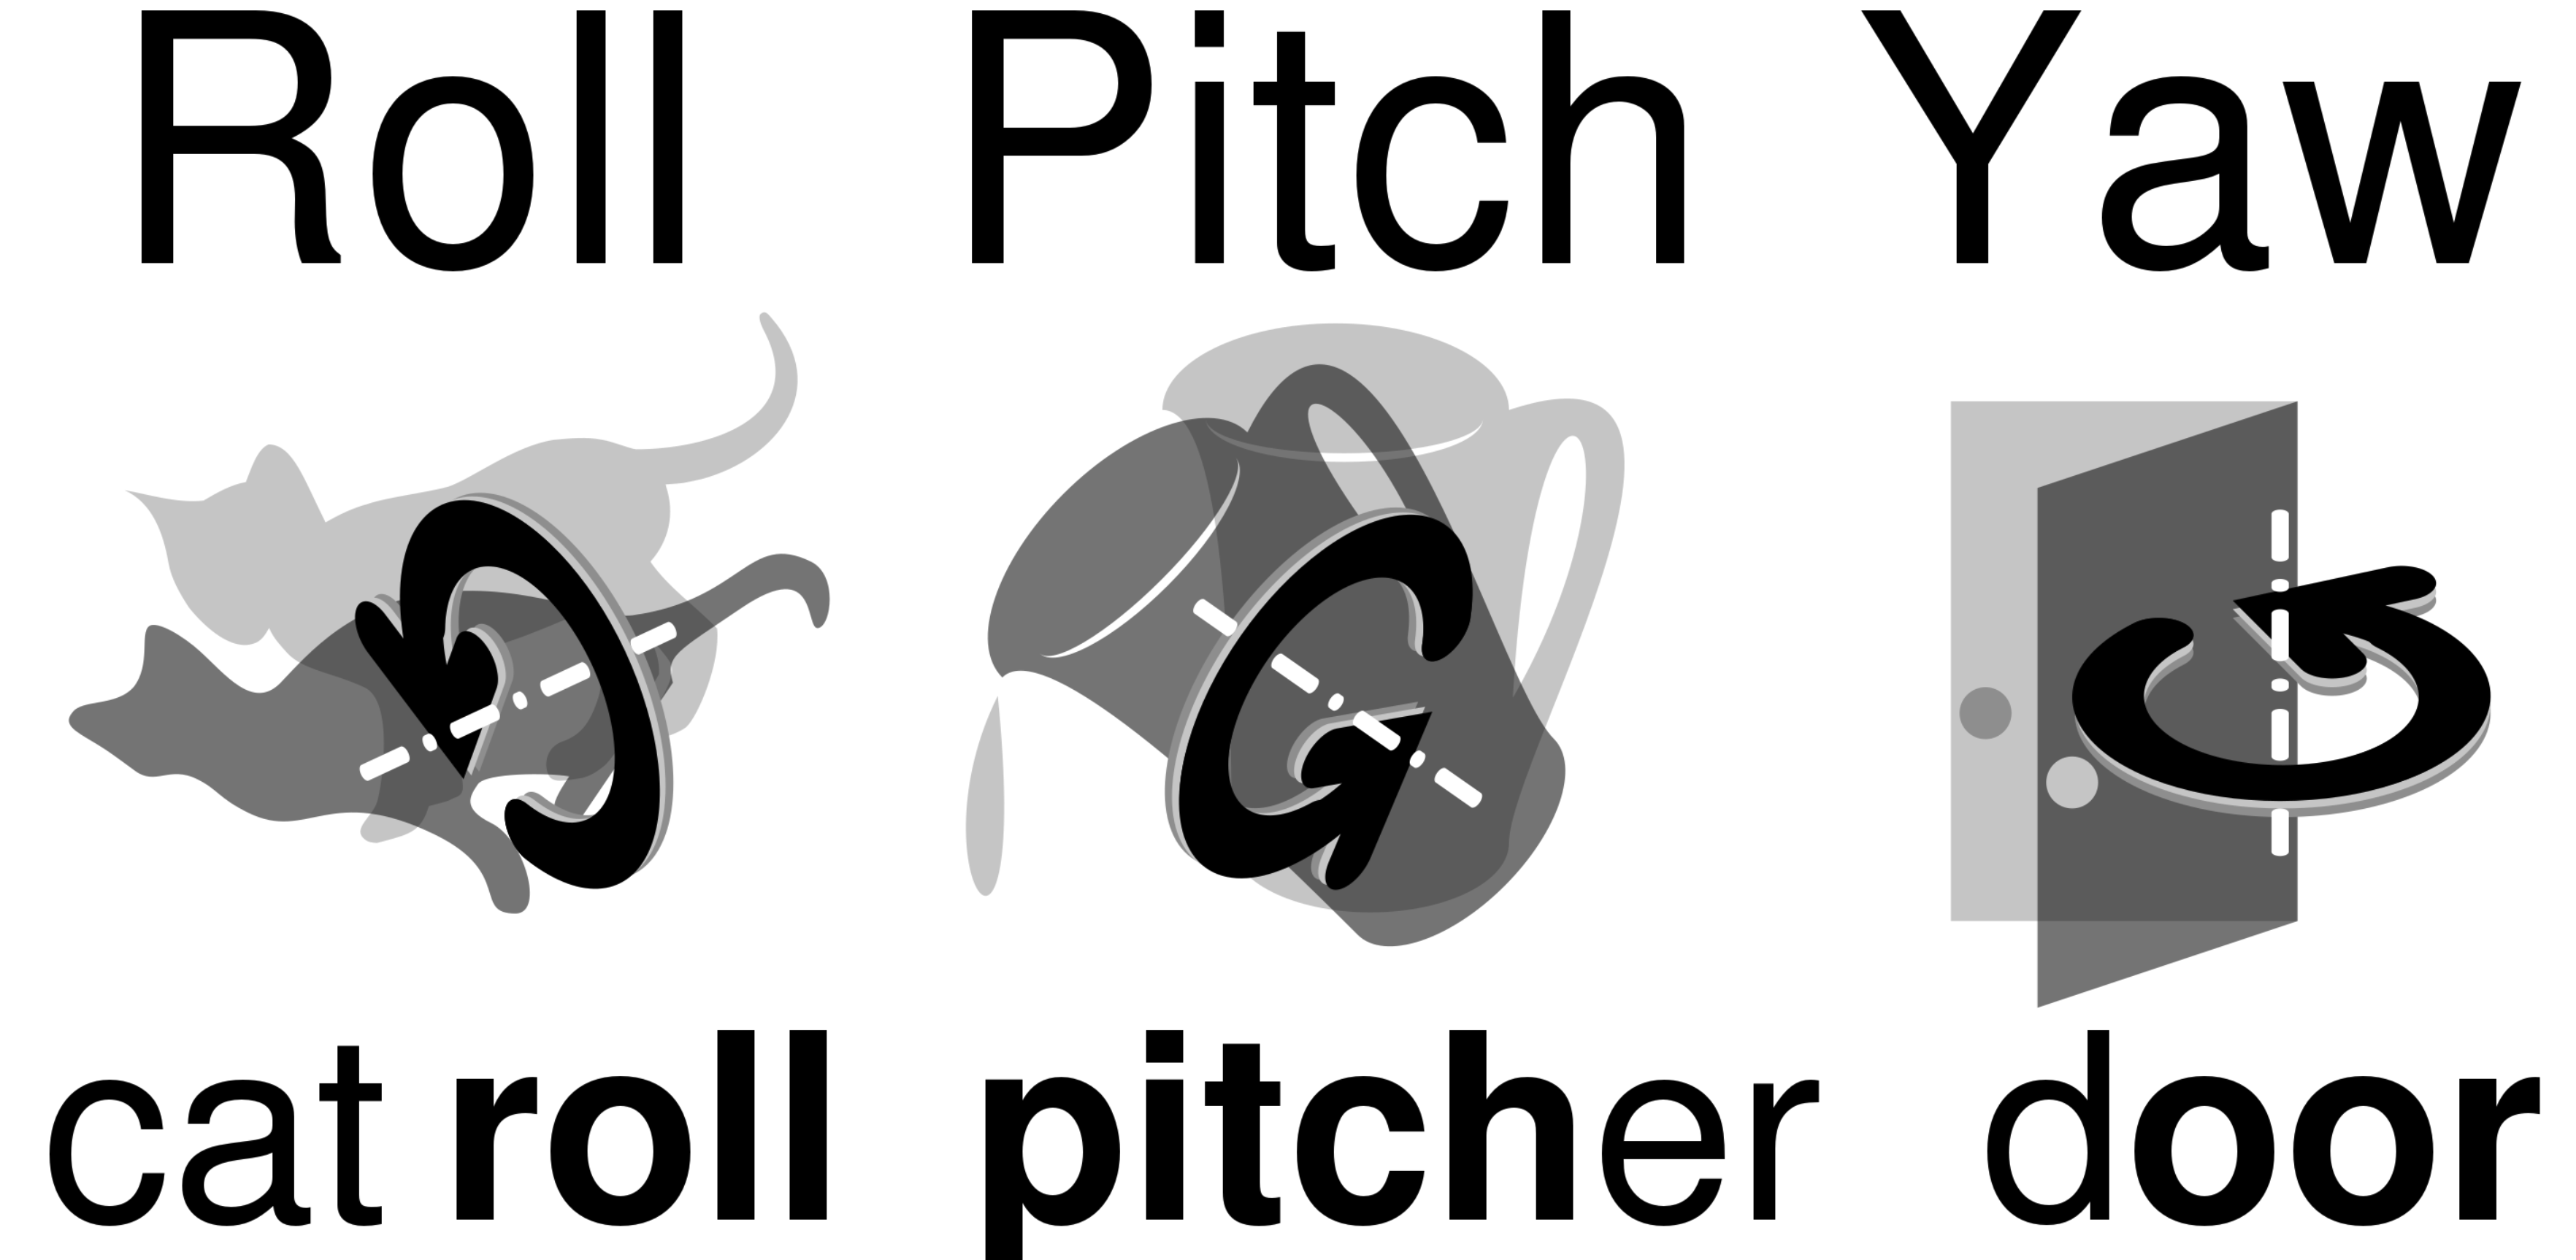

**Figure 3.2:** Mnemonics to remember the roll, pitch and yaw angle rotation axes [[5]](https://commons.wikimedia.org/wiki/%20File:Roll_pitch_yaw_mnemonic.svg).


The code block below can be used to visualise the workings of Euler angles in the four different frames that show the progression from $\{W\}$ to $\{B\}$, namely


$$\{W\} \rightarrow \{Z\} \rightarrow \{Y\} \rightarrow \{B\}.$$


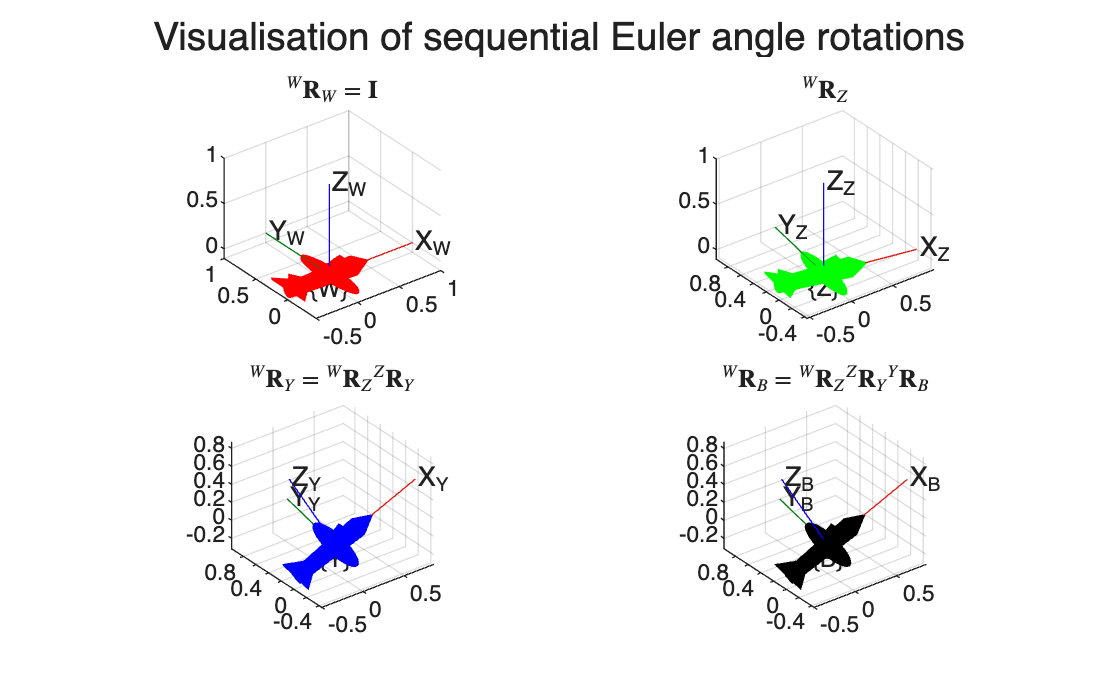

phi = 0*pi/180;    %define roll angle about x axis of {Y}
the = -30*pi/180;     %define pitch angle about y axis of {Z}
psi = -10*pi/180;    %define yaw angle about z axis of {W}

Rz = [cos(psi) -sin(psi) 0;                 %principal z-axis rotation matrix
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(the)   0   sin(the);              %principal y-axis rotation matrix
      0          1       0;
     -sin(the)   0   cos(the)];
Rx = [1     0        0;                     %principal x-axis rotation matrix
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];

%plot figures
figure,hold on
subplot(2,2,1),plotTransforms([0 0 0],rotm2quat(eye(3)),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf R}_W={\bf I}$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],rotm2quat(Rz),"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf R}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],rotm2quat(Rz*Ry),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf R}_Y={^W{\bf R}_Z}{^Z{\bf R}_Y}$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],rotm2quat(Rz*Ry*Rx),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf R}_B={^W{\bf R}_Z}{^Z{\bf R}_Y}{^Y{\bf R}_B}$',Interpreter='latex'),grid on

sgtitle('Visualisation of sequential Euler angle rotations')

While the *Z-Y-X* rotation order is fairly common in engineering (especially aeronautics and aerial robotics), we could have actually chosen from a multitude of rotation orders. Our only constraint is that we cannot rotate about the same axis sequentially, as that would be equivalent to a single rotation by the sum of the two angles. The twelve valid rotation orders are:


$$\begin{array}{cc}    XYX, XZX, YXY, YZY, ZXZ, ZYZ, XYZ, XZY, YZX, YXZ, ZXY, ZYX\\ \end{array}$$


### 3.2.2 Gimbal lock

Different industries and manufacturers will use different rotation conventions, selecting one from above, but it is important to note there is technically no right or wrong version. However, one crucial point to be aware of is that an Euler angle representation of orientation always exhibits a singularity when any two rotation axes become parallel or anti-parallel. This phenomenon is commonly referred to as **gimbal lock**. 

#### **Definition: Gimbal lock**

**Gimbal lock** is the loss of one degree of freedom in a three-dimensional, three-gimbal mechanism that occurs when the axes of two of the three gimbals are driven into a parallel configuration, "locking" the system into rotation in a degenerate two-dimensional space. 

For the set of Euler angle rotation orders with repeated axes (sometimes referred to as *Eulerian*), namely


$$\begin{array}{cc}    XYX, XZX, YXY, YZY, ZXZ, ZYZ,  \end{array}$$


gimbal lock will occur when the second angle of rotation equals $0+k\pi$, where $k\in \mathbb{Z}$, as this will make the first and third rotation axis align.

For the set of Euler angles with no repeated axes (sometimes referred to as *Cardian*), namely


$$\begin{array}{cc}    XYZ, XZY, YZX, YXZ, ZXY, ZYX,\\ \end{array}$$


gimbal lock will occur when the second angle of rotation equals $\pm \frac{\pi}{2}$, as this will make the first and third rotation axis align. 

In summary, regardless of the Euler rotation convention, gimbal lock will occur when the first and third rotation axes are aligned. Physically, this means that rotations about the first and third axis cannot be differentiated apart, and are instead summed, as a result of degenerate 2D space. Figure 3.3 below gives a visualisation of gimbal lock.

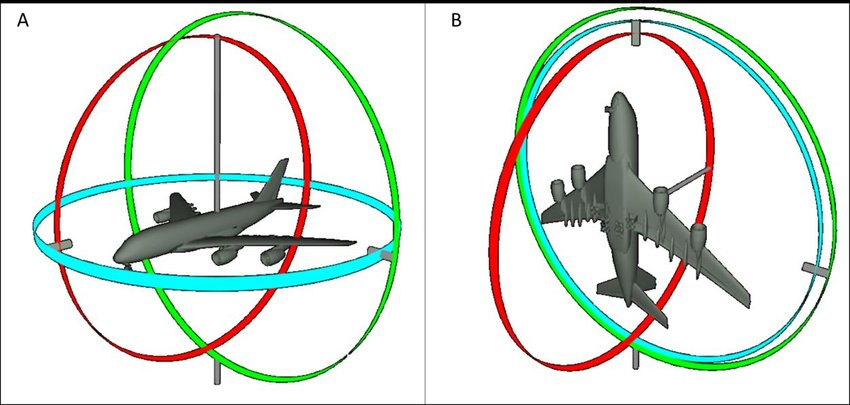

**Figure 3.3:** Visualisation of the three rotational axes (facilitated by imaginary gimbals) attached to an airplane. Left: nominal condition with none of the axes aligned. Right: Two of the gimbals become aligned causing a loss of information in one of the axes and resulting in a singularity [[6]](https://www.researchgate.net/figure/Gimbal-lock-problem-for-Euler-angles-A-no-gimbal-lock-B-yaw-and-roll-angles-are_fig14_332394380)
 

So if you plan to use Euler angles, you need to be cognizant of how the angular behaviour is going to evolve. If the operating region contains Euler angles that cause the first and last rotation axes to become parallel, then consider re-framing how you have defined your reference frame, or use a different rotation order to circumvent the potential for gimbal lock. [This](https://www.youtube.com/watch?v=-WXfEPg8eMM&feature=youtu.b) video provides a good explanation of gimbal lock and the singularity problem. 

### 3.2.3 Extracting Euler angles

The Euler-parameterised rotation matrix of


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    \end{array}$$


shows us how to populate a rotation matrix given our Z-Y-X ordering, ${^W{\mathbf R}_B}={\mathbf R}({^W\mathbf\eta_B})$, but we can also extract Euler angle information from a rotation matrix if required:  


$$^W\mathbf\eta_B={\mathbf R}^{-1}({^W{\mathbf R}_B}).$$


We may, for example, need Euler angle information to visualise how our robot is oriented, or we may want to make use of that information within a control loop (e.g. regulating the yaw angle of a manipulator arm). Denoting the row $x$ and column $y$ element of the rotation matrix ${\bf R}$ as $r_{xy}$, namely


$$\begin{array}{cc}^W{\mathbf R}_B = \left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]=    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    .\end{array}$$


the corresponding Euler angles can be extracted using


$$\begin{array}{cc}\phi = \arctan(\frac{r_{32}}{r_{33}})\end{array},$$



$$\begin{array}{cc}\theta = -\arcsin{r_{31},\end{array}$$



$$\begin{array}{cc}\psi = \arctan(\frac{r_{21}}{r_{11}}).\end{array}$$


Importantly, this result is only valid for *Z-Y-X* intrinsic Euler angles. 

phi = -40*pi/180;    %set roll angle about x axis of {Y}
the = 90*pi/180;     %set pitch angle about y axis {Z}
psi = -30*pi/180;    %set yaw angle about z axis of {W}

Rz = [cos(psi) -sin(psi) 0; %principle rotation about z-axis
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(the)   0   sin(the);  %principle rotation about y-axis
      0          1       0;
     -sin(the)   0   cos(the)];
Rx = [1     0        0;     %principle rotation about x-axis
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];
R = Rz*Ry*Rx;    %combining all three rotations into 3D rotation matrix

%extracting Euler angles using formula above.
phi_ = atan2( R(3,2),R(3,3) )*180/pi

phi_ = -40

theta_ = -asin( R(3,1) )*180/pi

theta_ = 90

psi_ = atan2( R(2,1),R(1,1) )*180/pi

psi_ = -30.0000

Note that in practice we make use of [`atan2`](https://in.mathworks.com/help/releases/R2024b/matlab/ref/double.atan2.html?overload=atan2+false) instead of `atan` when performing the calculations to determine $\phi$ and $\psi$, as this takes into account the full possible range of $\{\phi,\psi\}\in[-\pi,\pi]$.

### 3.2.4 Intrinsic and extrinsic rotations

Recall our Euler angle result of


$$\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}, \end{array}$$


which we assembled from left to right using the ordering of 


$$\{W\} \rightarrow \{Z\} \rightarrow \{Y\} \rightarrow \{B\}.$$
 

Notably, we can also think of constructing the result above, building instead from *right to left*, by starting in $\{B\}$ and then: 

- performing a rotation of $\phi$ about ${\hat{\bf x}_W}$, 

- followed by a rotation of $\theta$ about $\hat{\bf y}_W$, 

- and then finally, a rotation of $\psi$ about $\hat{\bf z}_W$. 

This gives us a clue about intrinsic and extrinsic rotations:

- when a frame is rotated about a vector in $\{B\}$, we should *post-multiply* the current orientation with the matrix describing the new rotation,

- when a frame is rotated about a vector in $\{W\}$, we should *pre-multiply* the current orientation with the matrix describing the new rotation.

#### Example: Intrinsic and extrinsic rotations

In this example the robot has a initial orientation described by 


$$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & 0 & -1 \\    0 & 1 & 0    \\ \end{array}\right]    .\end{array}$$


If the robot then experiences a rotation of $\psi$ about $\hat{\bf z}_B$, we can describe the resulting orientation as 


$$\begin{array}{cc}{\mathbf R}{\bf R}_z = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & 0 & -1 \\    0 & 1 & 0    \\ \end{array}\right]
\left[\begin{array}{cccccccc}    \cos\psi & -\sin\psi & 0 \\    \sin\psi & \cos\psi & 0 \\    0 & 0 & 1    \\ \end{array}\right]    ,\end{array}$$


which is obtained by post-multiplying ${\bf R}$ by ${\bf R}_z$. This constitutes an intrinsic rotation.

If instead, the robot with initial orientation of ${\bf R}$ experiences a rotation of $\psi$ about $\hat{\bf z}_W$, we can describe the resulting orientation as 


$$\begin{array}{cc}{\bf R}_z{\mathbf R} = 
\left[\begin{array}{cccccccc}    \cos\psi & -\sin\psi & 0 \\    \sin\psi & \cos\psi & 0 \\    0 & 0 & 1    \\ \end{array}\right] \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & 0 & -1 \\    0 & 1 & 0    \\ \end{array}\right]   ,\end{array}$$


which is obtained by pre-multiplying ${\bf R}$ by ${\bf R}_z$. This constitutes an extrinsic rotation.

The code block below provides a visual representation of this.

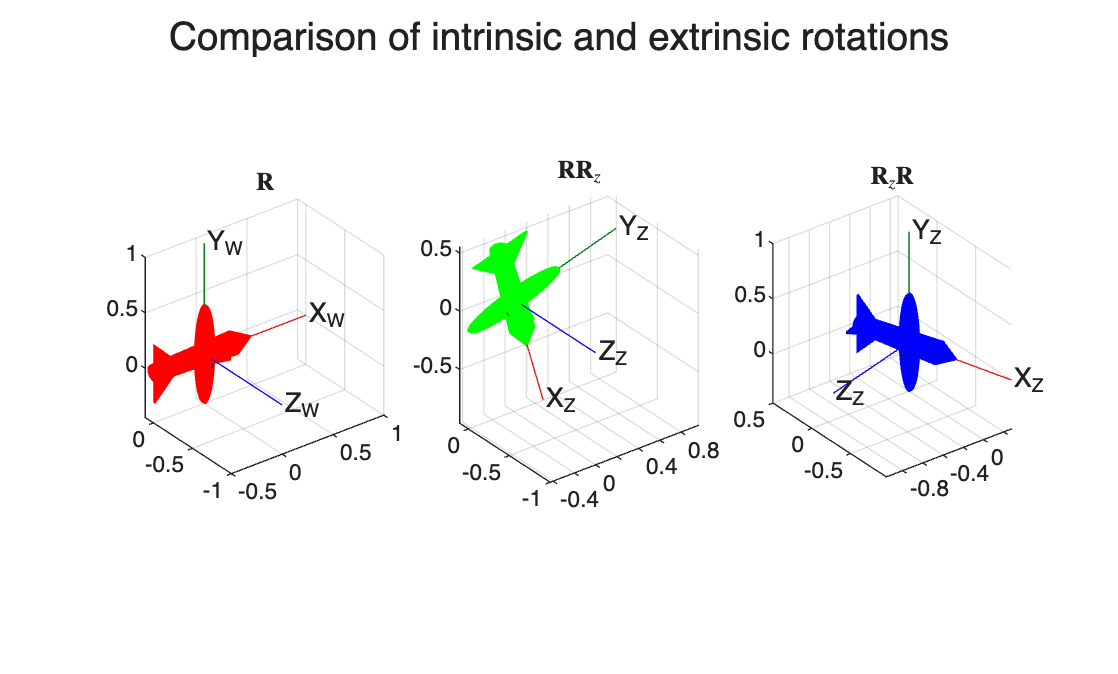

psi = -74*pi/180;

Rz = [cos(psi) -sin(psi) 0; %principle rotation about z-axis
      sin(psi) cos(psi) 0;
      0          0       1];

R = [1 0  0;    %initial orientation of robot
     0 0 -1;
     0 1  0];

R1 = R*Rz;    %new orientation after intrinsic rotation about z axis
R2 = Rz*R;    %new orientation after extrinsic rotation about z axis

%plot figures
figure,hold on
subplot(1,3,1),plotTransforms([0 0 0],rotm2quat(R),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('${\bf R}$',Interpreter='latex'),grid on
subplot(1,3,2),plotTransforms([0 0 0],rotm2quat(R1),"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('${\bf R}{\bf R}_z$',Interpreter='latex'),grid on
subplot(1,3,3),plotTransforms([0 0 0],rotm2quat(R2),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('${\bf R}_z{\bf R}$',Interpreter='latex'),grid on
sgtitle('Comparison of intrinsic and extrinsic rotations')

## 3.3 Quaternions 

Euler angles are appealing as an introduction to understanding orientation, as they are intuitively pleasing and relatively easy to visualise. However, the potential for our orientation representation becoming degenerate and resulting in kinematic singularities raises a red flag for many robotic applications. Additionally, the idea of describing an orientation using three sequential rotations does not follow how rigid-body robot motion will evolve in general. Instead, we would expect pure rotations about some arbitrary axis — enter the quaternion! 

The **quaternion** is a popular choice of encoding attitude that can completely avoid the issue of gimbal lock by rather describing the orientation as a single rotation about some defined axis that intercepts the relevant reference frame origin. At first glance, the quaternion can seem a bit daunting, but the benefits of understanding and being able to utilise it in robotics (among other fields) is worth the time investment that you may need to understand it. We will also see later in Section 3.4 that quaternions are closely related to exponential coordinates — another powerful and yet intuitive way to describe orientation.

### 3.3.1 Definition

The quaternion, $\bf q$ , is a 4-element vector (also known as a 4-tuple) and is structured as


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    q_0 \\ q_x \\ q_y \\ q_z    \\ \end{array}\right],\end{array}$$


in which$\{q_0, q_x, q_y,q_z\}$ are real numbers. In the context of describing orientation, we only consider *unit quaternions*, which gives us the unit-norm constraint of


$$\begin{array}{cc} |{\bf q}|=q_0^2+ q_x^2+ q_y^2+ q_z^2 = 1.\end{array}$$


Explicitly, the unit quaternion follows an *angle-axis* structure of 


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf n}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right],\end{array}$$


where  $\hat{\mathbf n}=[n_x ~n_y ~n_z]^T$ is the unit-length ( $|\hat{\mathbf n}|=1$ ) rotation axis, and  $\alpha \in [-\pi,\pi)$ is the rotation angle, as shown in Figure 3.4 for the case when the rotation vector is described with respect to $\{W\}$.

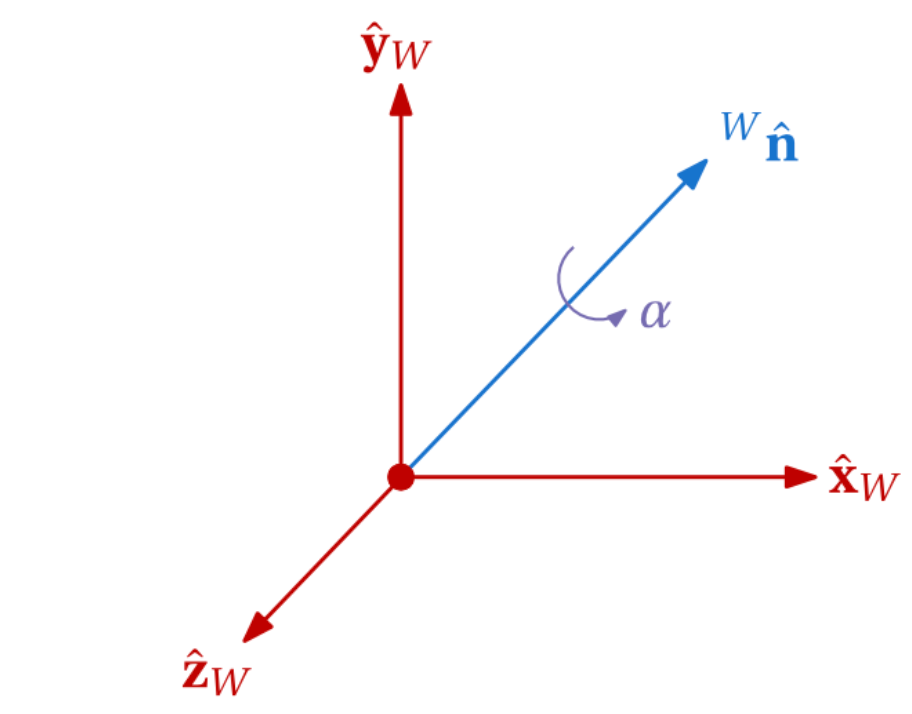

**Figure 3.4:** Visualisation of a quaternion-based rotation about vector ${^W\hat{\bf v}}$ with rotational angle $\alpha$.

The code block below also shows how the quaternion axis-angle form can be used to rotate a rigid body, such as a quadcopter. The black line shows the rotation axis, $\hat{\bf n}$.

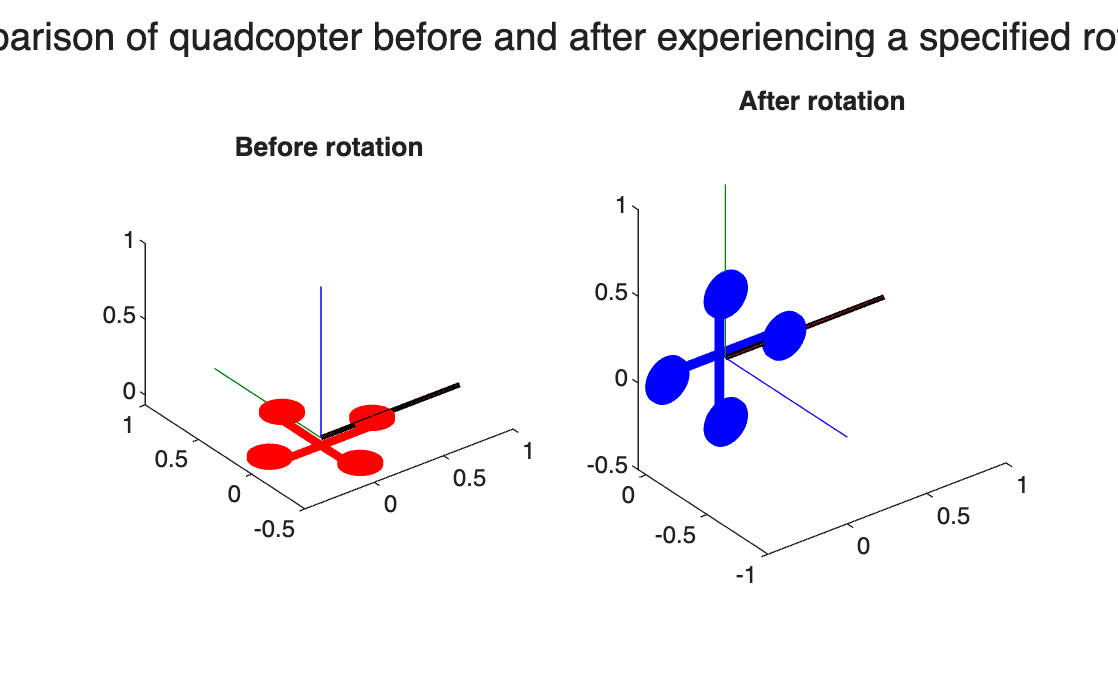

n_x = 1;
n_y = 0;
n_z = 0;
n = [n_x n_y n_z]'; 
n = n/norm(n);  %normalise v so that it always has unit length.

alpha = 90*pi/180;
q = [cos(alpha/2); sin(alpha/2)*n];

figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'multirotor.stl',"MeshColor","red")
line([0 n(1)],[0,n(2)],[0,n(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation')

subplot(1,2,2)
plotTransforms([0 0 0],q',"MeshFilePath",'multirotor.stl',"MeshColor","blue")
line([0 n(1)],[0,n(2)],[0,n(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation') 
sgtitle('Comparison of quadcopter before and after experiencing a specified rotation')

The explicit quaternion form of


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf n}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} n_x \\    \sin{\frac{\alpha}{2}} n_y \\    \sin{\frac{\alpha}{2}} n_z    \\ \end{array}\right]
=     \left[\begin{array}{cc}    q_0 \\     q_x \\    q_y \\    q_z    \\ \end{array}\right]
\end{array}$$


 is a way of *encoding* the 3D rotation of $\alpha$ about $\hat{\bf v}$ in a useful format, analogous to how rotation matrices encode attitude. Assuming we are given ${\bf q } = \left[q_0 ~~ q_x ~~ q_y ~~ q_z \right]^T$, we can always extract the angle-axis information from our quaternion representation using 


$$\begin{array}{cc}\alpha = 2\cos^{-1}(q_0),\end{array}$$


and 


$$\begin{array}{cc}\hat{\mathbf n} = \frac{1}{\sin{\frac{\alpha}{2}}}\left[\begin{array}{cc}    q_x \\ q_y \\ q_z    \\ \end{array}\right] =     \frac{1}{\sqrt{1-q_0^2}}    \left[\begin{array}{cc}    q_x \\ q_y \\ q_z    \\ \end{array}\right].\end{array}$$


When  $q_0=1$ , (which implies that  $\alpha=0$ ), the equation above tends to infinity, making the rotation axis become undefined. However, this is not problematic, as $\alpha=0$ corresponds to the null rotation matrix of  ${\mathbf R}={\mathbf I}$. In essence, we cannot determine the rotation vector because there is no rotation taking place. In this case, we would describe the identity (or null) quaternion as  ${\mathbf q}_{\mathbf I}=[1~ 0~ 0~ 0]^T$ . Given an angle-axis combination, we can now describe the corresponding quaternion


$$\{\alpha,\hat{\mathbf n}\}\rightarrow {\mathbf q},$$


and similarly, given a quaternion, we can recover our angle-axis pair


$${\mathbf q}\rightarrow \{\alpha,\hat{\mathbf n}\}.$$


For example, if we wanted to rotate about the $\hat{\mathbf z}_W$-axis by an angle $\alpha=\psi$, our rotation axis would be  $\hat{\mathbf n}=\hat{\mathbf z}_W=[0 ~0~ 1]^T$ , resulting in


$$\begin{array}{cc}{^W{\mathbf q}}_Z = \left[\begin{array}{cc}          \cos{\frac{\psi}{2}} \\          0 \\          0 \\          \sin{\frac{\psi}{2}}          \\ \end{array}\right].\end{array}$$


Note that this quaternion is analogous to the principle $z$-axis rotation matrix of


$$\begin{array}{cc}{^W\mathbf R_Z} = \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


The method of encoding the orientation is just different. Fortunately, there does exist a one-to-one mapping between the quaternion representation and rotation matrix, given by


$$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    2(q_0^2+q_x^2)-1 & 2(q_xq_y-q_0q_z) & 2(q_xq_z+q_0q_y) \\    2(q_xq_y+q_0q_z) & 2(q_0^2+q_y^2)-1 & 2(q_yq_z-q_0q_x) \\    2(q_xq_z-q_0q_y) & 2(q_yq_z+q_0q_x) & 2(q_0^2+q_z^2)-1    \\ \end{array}\right],\end{array}$$


and unsurprisingly, by substituting our result for ${^W{\mathbf q}}_Z$ into $\bf R$ above, we obtain $^W{\bf R}_Z$. 

For $q_0\neq 0$, which implies that $\alpha \neq \pm \pi$, extraction of the quaternion from a rotation matrix is achieved using

$q_0=\frac{1}{2}\sqrt{1+\text{tr}{\bf R}},$     $q_x=\frac{r_{32}-r_{23}}{4q_0}$,     $q_y=\frac{r_{13}-r_{31}}{4q_0}$,      $q_z=\frac{r_{21}-r_{12}}{4q_0},$

where 

$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    2(q_0^2+q_x^2)-1 & 2(q_xq_y-q_0q_z) & 2(q_xq_z+q_0q_y) \\    2(q_xq_y+q_0q_z) & 2(q_0^2+q_y^2)-1 & 2(q_yq_z-q_0q_x) \\    2(q_xq_z-q_0q_y) & 2(q_yq_z+q_0q_x) & 2(q_0^2+q_z^2)-1    \\ \end{array}\right]\end{array}=\left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]$.

If $q_0=0$, implying that  that $\alpha = \pm \pi$, the equation above for determining the vector part of $\bf q$ will result in a singularity. In this case, we can instead determine $\{q_x,q_y,q_z\}$ using

$q_x=\sqrt{\frac{r_{11}+1}{2}}$,     $q_y=\sqrt{\frac{r_{22}+1}{2}}$,     $q_z=\sqrt{\frac{r_{33}+1}{2}}$.

### 3.3.2 Quaternion multiplication

While the mapping from $\bf q$ to $\bf R$ is a nice sanity check on things, we are losing one of the benefits of the quaternion, and that is its mathematical efficiency. Just as we were able to sequentially construct our body-frame orientation by using the elementary rotations when dealing with Euler angles, we can follow a similar process for the quaternion. However, we first need to cover how quaternion multiplication works. Given two quaternions, $\bf q$ and $\bf r$ , the quaternion product (or Hamilton Product), indicated using the symbol $\otimes$, is defined as


$$\begin{array}{cc}{\mathbf q} \otimes {\mathbf r} =     \left[\begin{array}{cc}    q_0r_0-q_xr_x-q_yr_y-q_zr_z \\    q_0r_x+r_0q_x+q_yr_z-r_yq_z \\    q_0r_y+r_0q_y+r_xq_z-q_xr_z \\    q_0r_z+r_0q_z+q_xr_y-r_xq_y    \\ \end{array}\right].\end{array}$$


This stems from the fact that $\bf q$ and $\bf r$ can be written as


$${\bf q} = q_0+q_x\hat{\bf i}+q_y\hat{\bf j}+q_z\hat{\bf k},$$


${\bf r} = r_0+r_x\hat{\bf i}+r_y\hat{\bf j}+r_z\hat{\bf k}$,

respectively, where $\{\hat{\bf i},\hat{\bf j},\hat{\bf k}\}$ are the basis vectors indicating direction. Using the relationship of


$$\hat{\bf i}^2=\hat{\bf j}^2=\hat{\bf k}^2=\hat{\bf i}\hat{\bf j}\hat{\bf k}=-1$$


yields the above-mentioned result of 


$$\begin{array}{ll}{\mathbf q} \otimes {\mathbf r} &=    
\left(q_0+q_x\hat{\bf i}+q_y\hat{\bf j}+q_z\hat{\bf k}\right)\left(r_0+r_x\hat{\bf i}+r_y\hat{\bf j}+r_z\hat{\bf k}\right)\\
&= \left( q_0r_0-q_xr_x-q_yr_y-q_zr_z \right)+\left(q_0r_x+r_0q_x+q_yr_z-r_yq_z  \right)\hat{\bf i}+\left( q_0r_y+r_0q_y+r_xq_z-q_xr_z \right)\hat{\bf j}+\left(q_0r_z+r_0q_z+q_xr_y-r_xq_y \right)\hat{\bf k}\\
&= \left[\begin{array}{cc}    q_0r_0-q_xr_x-q_yr_y-q_zr_z \\    q_0r_x+r_0q_x+q_yr_z-r_yq_z \\    q_0r_y+r_0q_y+r_xq_z-q_xr_z \\    q_0r_z+r_0q_z+q_xr_y-r_xq_y    \\ \end{array}\right].
\end{array}$$


The result above can be written compactly as


$$\begin{array}{ll}{\mathbf q} \otimes {\mathbf r}
&= \left[\begin{array}{cc}    q_0r_0-\vec{\bf q}\cdot{} \vec{\bf r}\\    q_0\vec{\bf r}+r_0\vec{\bf q}+\vec{\bf q}\times \vec{\bf r} \end{array}\right],
\end{array}$$


where $\vec{\bf q}=[q_x~~q_y~~q_z]^T$ and $\vec{\bf r}=[r_x~~r_y~~r_z]^T$. 

Continuing with our exercise of emulating the sequential construction of our body-frame orientation as was done using ZYX Euler angles, we begin by configuring the two reference frames such that they are aligned and coincident. We then apply a rotation about  $\hat{\mathbf z}_W=[0~0~1]^T$ , with an angle of $\psi$, which gives us 


$$\begin{array}{cc}{^W{\mathbf q}}_Z = \left[\begin{array}{cc}          \cos{\frac{\psi}{2}} \\          0 \\          0 \\          \sin{\frac{\psi}{2}}          \\ \end{array}\right].\end{array}$$


We next rotate about  $\hat{\mathbf y}_Z=[0~1~0]^T$ with an angle of  $\theta$, which is encoded by the incremental quaternion of 


$$\begin{array}{cc}^Z{\mathbf q}_Y = \left[\begin{array}{cc}          \cos{\frac{\theta}{2}} \\          0 \\          \sin{\frac{\theta}{2}}\\          0           \\ \end{array}\right].\end{array}$$


Lastly, we rotate about  $\hat{\mathbf x}_Y=[1~0~0]^T$, with an angle of  $\phi$, which is described by the incremental quaternion of 


$$\begin{array}{cc}^Y{\mathbf q}_B = \left[\begin{array}{cc}          \cos{\frac{\phi}{2}} \\          \sin{\frac{\phi}{2}}\\          0 \\          0           \\ \end{array}\right].\end{array}$$


Our full description of the body-frame orientation, using the quaternion as our *encoder* follows as


$$\begin{array}{cc}{^W{\mathbf q}_B}={^W{\mathbf q}_Z} \otimes {^Z{\mathbf q}_Y} \otimes {^Y{\mathbf q}_B},\end{array}$$


and is analogous to the rotation matrix equivalent of $\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}.\\ \end{array}$ The code block below shows how to perform quaternion multiplication in `MATLAB `and also illustrates that the quaternion representation of attitude matches that of the rotation matrix counterpart.

phi = 90*pi/180;    %set roll angle about x axis of {Y}
the = 30*pi/180;     %set pitch angle about y axis of {Z}
psi = 0*pi/180;    %set yaw angle about z axis of {W}

q_z2w = [cos(psi/2) 0 0 sin(psi/2)];    %quaternion representation of yaw rotation about z in {W}
q_y2z = [cos(the/2) 0 sin(the/2) 0];    %quaternion representation of pitch rotation about y in {Z}
q_b2y = [cos(phi/2) sin(phi/2) 0 0];    %quaternion representation of roll rotation about x in {Y}

q_b2w = quatmultiply( quatmultiply(q_z2w,q_y2z), q_b2y )    %full quaternion describing orientation of {B} wrt {W}

q_b2w =     0.6830    0.6830    0.1830   -0.1830


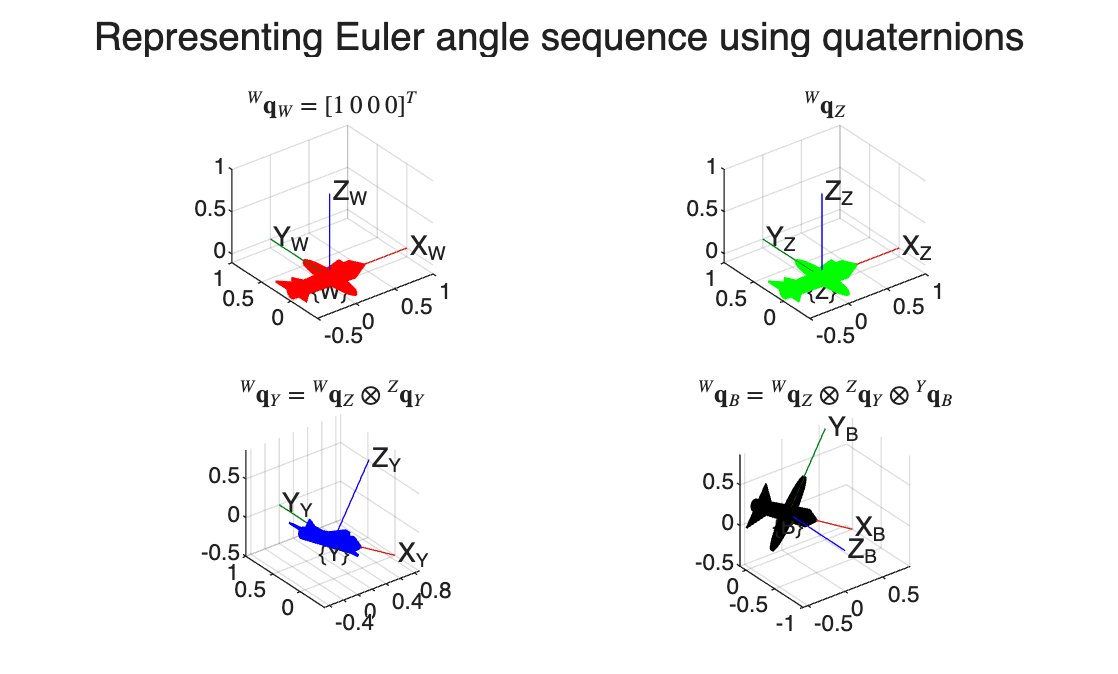


%plot figures
figure,hold on,sgtitle('Representing Euler angle sequence using quaternions')
subplot(2,2,1),plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf q}_W=[1~0~0~0]^T$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],q_z2w,"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf q}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],quatmultiply(q_z2w,q_y2z),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf q}_Y={^W{\bf q}_Z}\otimes {^Z{\bf q}_Y}$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],quatmultiply( quatmultiply(q_z2w,q_y2z),q_b2y),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf q}_B={^W{\bf q}_Z}\otimes {^Z{\bf q}_Y}\otimes {^Y{\bf q}_B}$',Interpreter='latex'),grid on

As with the Euler angles, we have followed the ordering of $\{W\} \rightarrow \{Z\} \rightarrow \{Y\} \rightarrow \{B\}.$ Quaternions can also be thought of as being intrinsic or extrinsic — when post-multiplying by a quaternion, we can imagine the rotation vector being described in the current frame (as above), whereas when pre-multiply the vector is described in $\{W\}$.

Note that in this particular case, our quaternions are still parameterised by the Euler angles. This is not how we will usually make use of quaternions; rather, this is a demonstration of how quaternion rotation works, and its relationship with Euler angles and rotation matrices.

It is worth highlighting the numerical efficiency of the quaternion — while multiplying two rotation matrices requires 27 multiplications and 18 additions, quaternion multiplication only requires 16 multiplications and 12 additions. This may seem insignificant, but in certain applications where processing power is limited, or a large number of coordinate mappings are required (e.g. in the video game industry) this FLOP saving is invaluable! 

As with the rotation matrix, the quaternion has an inverse, defined as


$$\begin{array}{cc}{\mathbf q}^{-1} = \left[\begin{array}{cc}    q_0 \\    -q_x \\    -q_y \\    -q_z    \\ \end{array}\right].\end{array}$$


We can think of this inverse in one of two ways: either 

- (i) the rotation vector changes direction and points in the opposite direction, or 

- (ii) the rotation angle changes direction. 

In either case, the quaternion inverse can be thought of as "undoing" a rotation. 

If we rotated our robot such that our quaternion was  ${\mathbf a}=[a_0 ~a_x ~a_y ~a_z]^T$ , followed by multiplication of the inverse,  ${\mathbf a}^{-1}=[a_0 ~-a_x ~-a_y ~-a_z]^T$ , we would return to our identity quaternion,  ${\mathbf a}^{-1}\otimes {\mathbf a}=[1 ~0 ~0 ~0]^T$ . 

alpha = 45*pi/180;    %set rotation angle
nx = [1 1 1];     %define arbitrary vector
nx = nx/norm(nx);    %set vector norm to one

q = [cos(alpha/2) sin(alpha/2)*nx];    %quaternion describing rotation

q_I = quatmultiply( quatinv(q),q )    %quaternion multiplied by its inverse, which always returns the null quaternion

q_I =      1     0     0     0


### 3.3.3 Rotating a frame

The sequential process of building a quaternion using the principal axis rotations is useful for demonstrating the parallel between rotation matrices and quaternions, but there is actually no need to ever use Euler angles when incorporating quaternions. As previously mentioned, the orientation can be defined using a rotation vector,  $\hat{\mathbf n}$ , and rotation angle $\alpha$ about  $\hat{\mathbf n}$ . In other words, we can define a mapping between two reference frames by either rotating about a single vector with a specific rotation angle (encoded as a quaternion), or equivalently performing three sequential rotations about the intrinsic axes (Euler-parameterised rotation matrix). 

The quaternion approach is generally quite appealing for robotics, as it matches the "natural" rotational behaviour of rigid bodies. That is, incremental rotations will occur as a single motion, not three discrete motions. Later Chapters will also demonstrate that quaternions are highly beneficial when confronting the rigid-body robotic trajectory generation, orientation estimation, and control problem, whereas Euler angles can become problematic in most cases. 

The code block below shows how rotation about a vector can be visualised, with the resulting pose after the rotation facilitated using quaternions.

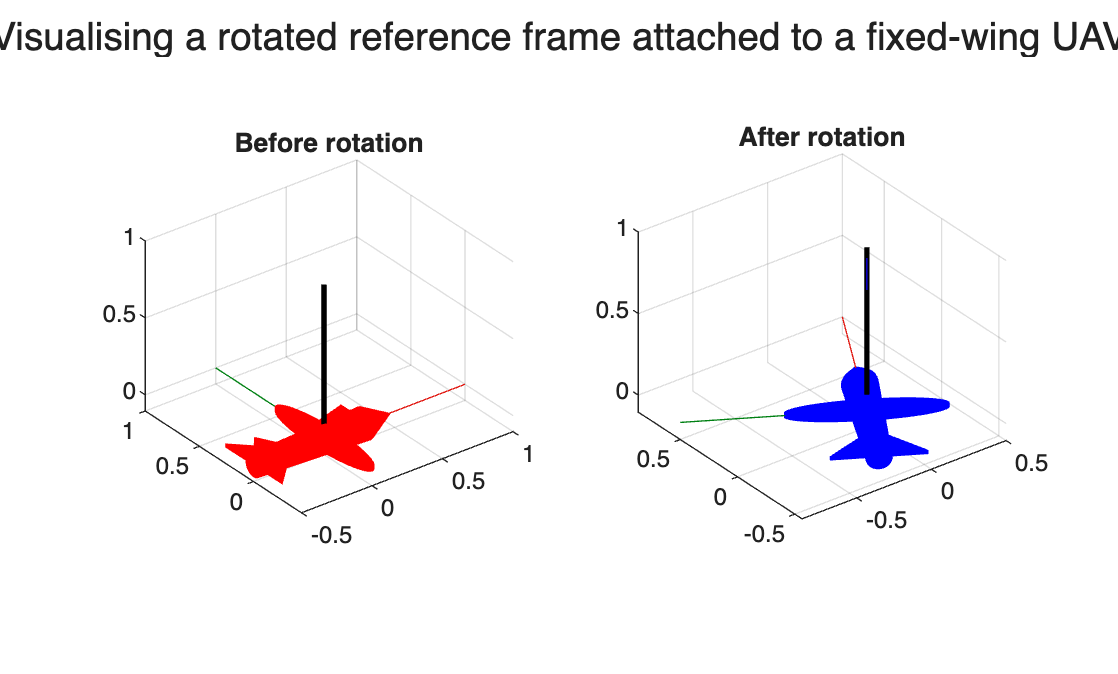

n_x = 0;    %x component of rotation vector
n_y = 0;    %y component of rotation vector
n_z = 1;    %z component of rotation vector
n = [n_x n_y n_z]';  %full rotation vector
n = n/norm(n);  %normalise vector so that it always has unit length

alpha = 60*pi/180;    %rotation angle
q = [cos(alpha/2); sin(alpha/2)*n];    %quaternion, formed from combination of rotation angle and rotation vector

%plot figures
figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red")
line([0 n(1)],[0,n(2)],[0,n(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation'),grid on

subplot(1,2,2)
plotTransforms([0 0 0],q',"MeshFilePath",'fixedwing.stl',"MeshColor","blue")
line([0 n(1)],[0,n(2)],[0,n(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation'),grid on

sgtitle('Visualising a rotated reference frame attached to a fixed-wing UAV')

### 3.3.4 Double cover

There is one *minor* caveat that should be made clear when using quaternions. We are operating in a 3D Euclidean space, but the quaternion is a $4$-element vector. So why does the quaternion have $4$ parameters to specify a 3D orientation? The simple answer is that a single quaternion does not uniquely define an orientation. That is, the orientation derived using a rotation about some axis is equivalent to a negative rotation about that same axis after it has been inverted. This results in a **double cover** phenomenon where  $\mathbf q$ and  $-{\mathbf q}$ represent the same rotation. 

The code block demonstrates this result in general, showing that orientation $\mathbf q$ and  $-{\mathbf q}$ are equivalent.

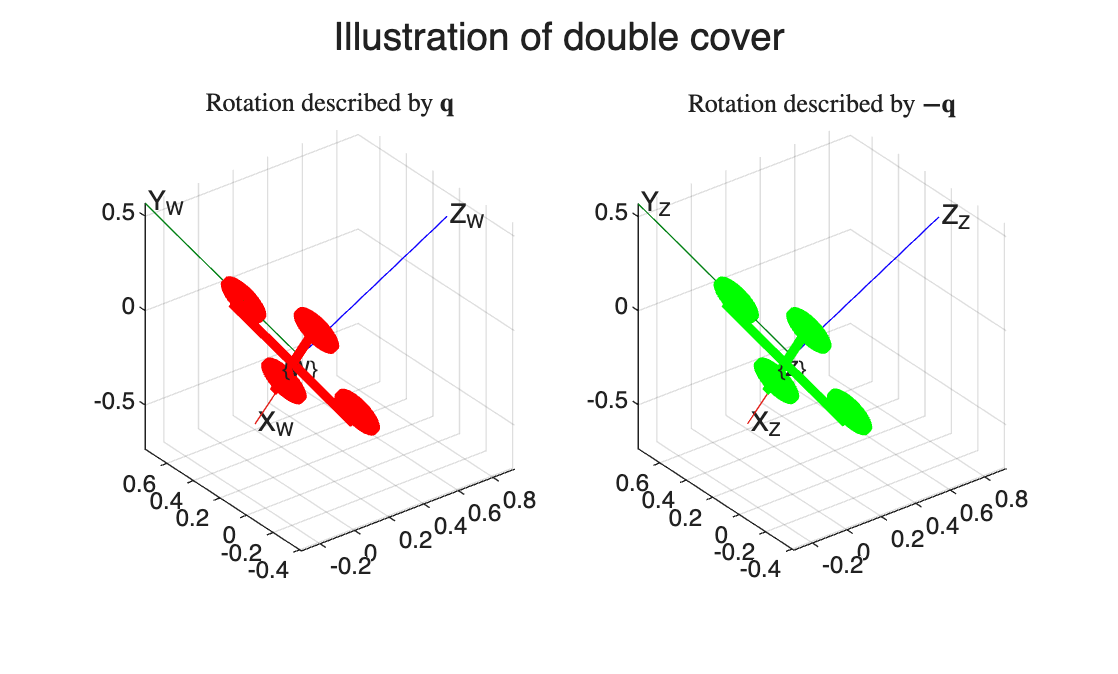

q0 = 1; %set scalar component of quaternion
qx = 0.2; %set x component of quaternion
qy = 0.7; %set y component of quaternion
qz = 0.4; %set z component of quaternion
q = [q0 qx qy qz]; %unnormalised quaternion
q = q/norm(q); %normalised quaternion

%plot figures
figure,hold on
subplot(1,2,1),plotTransforms([0 0 0],q,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title(['Rotation described by ','$\bf q$'],Interpreter='latex'),grid on
subplot(1,2,2),plotTransforms([0 0 0],-q,"MeshFilePath",'multirotor.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title(['Rotation described by ','$\bf -q$'],Interpreter='latex'),grid on
sgtitle('Illustration of double cover')

#### **Example: Double cover**

You rotate an arbitrary reference frame about a specified rotation vector,  $\hat{\mathbf n}$, by some angle  $\phi$, giving us the quaternion  

${\mathbf q}_1=[\cos(\phi/2) \hat{\mathbf n}^T \sin(\phi/2)]^T$ . 

If we had decided to instead rotate about the same rotation vector but in the opposite direction with a rotation angle of  $\phi-2\pi$ , our quaternion would follow as 


$${\mathbf q}_2=[\cos(\frac{\phi-2\pi}{2}) \quad\hat{\mathbf n}^T \sin(\frac{\phi-2\pi}{2})]^T=[\cos(\phi/2-\pi) \quad\hat{\mathbf n}^T \sin(\phi/2-\pi)]^T.$$


Noting the periodic nature of the $\cos$ and $\sin$ functions, we can make use of  $\sin({x-\pi})=-\sin{x}$ and  $\cos({x-\pi})=-\cos{x}$ to reduce  ${\mathbf q}_2$ to  

${\mathbf q}_2=[-\cos(\phi/2) \quad-\hat{\mathbf n}^T \sin(\phi/2)]^T=-{\mathbf q}_1$.

As a result of this double covering, every orientation will map to two quaternions; one that describes the minimum angle rotation, $|\alpha|\leq \pi$, and the other describing the maximum angle rotation, $|\alpha|\geq \pi$. The only exception is the special case where the rotation angle is $180^\circ$ , making both rotations equivalent in terms of angular distance. This disparity between a minimum and maximum angle rotation becomes important when our robot is trying to follow a path or correct an angular error, as we commonly desire minimal angular changes that result in smaller time and energy requirements (the minimum angle rotation). This is often referred to as the geodesic.

### 3.3.5 Rotating vectors

We have already shown that quaternions can be used to 

- represent orientation and 

- rotate frames. 

Analogous to rotation matrices, quaternions also possess the third property of being able to map vectors between frames. We will not explore this in detail in this course, but the following formulation can be used to rotate vector ${\bf p}$ between two frames, such as from $\{B\}$ to $\{W\}$:


$$\begin{array}{cc}
\left[\begin{array}{cc}    0 \\    {^W{\bf p}}\ \end{array}\right] = 
{^W{\mathbf q}_B} \otimes  \left[\begin{array}{cc}    0 \\    {^B{\bf p}}\ \end{array}\right] \otimes {^W{\mathbf q}^{-1}_B} .\end{array}$$


Note that this is equivalent to the rotation matrix form of


$${^W{\bf p}}={^W{\bf R}_B}{^B{\bf p}},$$


albeit less convenient to express mathematically when chaining together multiple sequential rotations.

pb = [1 2 3]';    %p wrt {B}

q = [1/sqrt(2) 0 1/sqrt(2) 0];    %quaternion describing orientation of {B} wrt {W}
R = quat2rotm(q);

pw = R*pb    %p wrt {W} using rotation matrix approach

pw =     3.0000
    2.0000
   -1.0000



pb_q = [0 pb']; %"quaternionised" p wrt {B}
pw_q = quatmultiply( quatmultiply(q, pb_q),quatinv(q) );  %calculate "quaternionised" p wrt {W}
pw_ = pw_q(2:4)'    %p wrt {W} using quaternion approach

pw_ =      3
     2
    -1


## 3.4 Exponential coordinates of rotations

### 3.4.1 Definition

Directly related to quaternions, **exponential coordinates** parameterise an orientation in terms of a rotation axis, represented by a unit vector $\hat{\bf n}$, and an angle of rotation $\alpha$; the vector $\alpha\hat{\bf n}\in \mathbb{R}^3$ then serves as the three-parameter exponential coordinate representation of the rotation. Writing $\hat{\bf n}$ and $\alpha$ individually is known as the **axis-angle** representation of a rotation and can be recovered from exponential coordinates of $\alpha\hat{\bf n}=[\theta_x ~~ \theta_y ~~ \theta_z]^T$ using


$$\alpha = \left| \alpha \hat{\bf n} \right|=\sqrt{\theta_x^2+\theta_y^2+\theta_z^2},$$



$$\hat{\bf n}=\frac{1}{\alpha}[\theta_x ~~ \theta_y ~~ \theta_z]^T=\frac{1}{\sqrt{\theta_x^2+\theta_y^2+\theta_z^2}}[\theta_x ~~ \theta_y ~~ \theta_z]^T.$$


Note that the rotation angle in this case will always be positive. 

Exponential coordinates can be used to describe orientation and can also be encoded in rotation matrices or quaternions to map vectors between frames. However, before we can show this result, we need to introduce the skew-symmetric matrix.

#### **Definition:** Skew-symmetric matrix

A **skew-symmetric matrix** is a square matrix whose transpose equals its negative: ${\mathbf S}^T=-{\mathbf S}$.

By this definition, the diagonal elements of  ${\mathbf S}$ must all equal zero in order to satisfy  ${\mathbf S}^T=-{\mathbf S}$ . Skew-symmetric matrices are useful in reposing a vector cross product operation as a matrix-vector multiplication, as we will show in a latter section. Given an arbitrary vector  ${\bf v}=[v_x ~v_y~v_z]^T$ , the corresponding skew-symmetric matrix is


$$\begin{array}{cc}\lfloor {\bf v} \rfloor = \left[\begin{array}{cccccccc}    0 & -v_z & v_y \\    v_z & 0 & -v_x \\    -v_y & v_x & 0    \\ \end{array}\right],\end{array}$$


which shows the symmetry across the diagonal, albeit with a sign change. Note the use of $\lfloor \dots \rfloor$ to indicate the skew-symmetric mapping.

As we will explore later in detail, if we wanted to evaluate a cross product operation such as  ${\bf v} \times {\mathbf p}$ , we could repose it as  ${\bf v} \times {\mathbf p}=\lfloor {\bf v} \rfloor{\mathbf p}$ , which is a vector multiplying into a matrix (not a cross product of two vectors). However, the result would remain the same. 

### 3.4.2 Exponential coordinates of SO(3)

It can be shown that a rotation matrix, parameterised using exponential coordinates, is given by the matrix exponential mapping


$${\bf R}=\mathrm{\bf e}^{\lfloor \alpha\hat{\bf n} \rfloor}=\mathrm{\bf e}^{\lfloor \hat{\bf n} \rfloor\alpha}.$$


Note that the matrix exponential differs from the standard single-element matrix exponential and in general is described by


$$\mathrm{\bf e}^{{\bf A}t}=I+t{\bf A}+\frac{t^2}{2!}{\bf A}^2+\frac{t^3}{3!}{\bf A}^3+\dots ,$$


where ${\bf A}\in \mathbb{R}^{n\times n$ is constant. For the special case when $\bf A$ is skew-symmetric, for example, ${\bf A}={\lfloor \hat{\bf n} \rfloor\alpha}$, the equation above can be reduced without loss of generality as


$${\bf R}=\mathrm{e}^{\lfloor \hat{\bf n} \rfloor\alpha}=I+\sin\alpha\lfloor \hat{\bf n} \rfloor +\left(1-\cos\alpha\right)\lfloor \hat{\bf n} \rfloor^2.$$


The equation above is known as **Rodrigues' formula **for rotations and is a convenient means of building a rotation matrix from exponential coordinates without having to evaluate the matrix exponential (an operation that can be computationally expensive on embedded hardware).

Writing out the above equation explicitly yields


$${\bf R}= \left[\begin{array}{cccccccc}    \mathrm{c}_\alpha+\hat{n}_x^2(1-\mathrm{c_\alpha}) & \hat{n}_x\hat{n}_y(1-\mathrm{c}_\alpha)-\hat{n}_z\mathrm{s}_\alpha & \hat{n}_x\hat{n}_z(1-\mathrm{c}_\alpha)+\hat{n}_y\mathrm{s}_\alpha \\    \hat{n}_x\hat{n}_y(1-\mathrm{c}_\alpha)+\hat{n}_z\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{n}_y^2(1-\mathrm{c_\alpha}) & \hat{n}_y\hat{n}_z(1-\mathrm{c}_\alpha)-\hat{n}_x\mathrm{s}_\alpha  \\    \hat{n}_x\hat{n}_z(1-\mathrm{c}_\alpha)-\hat{n}_y\mathrm{s}_\alpha & \hat{n}_y\hat{n}_z(1-\mathrm{c}_\alpha)+\hat{n}_x\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{n}_z^2(1-\mathrm{c_\alpha})    \\ \end{array}\right],$$


where $\hat{\bf n}=[\hat{n}_x~\hat{n}_y~\hat{n}_z]^T$, using the shorthand notation of $\mathrm{s}_\alpha=\sin{\alpha}$ and $\mathrm{c}_\alpha=\cos{\alpha}$.

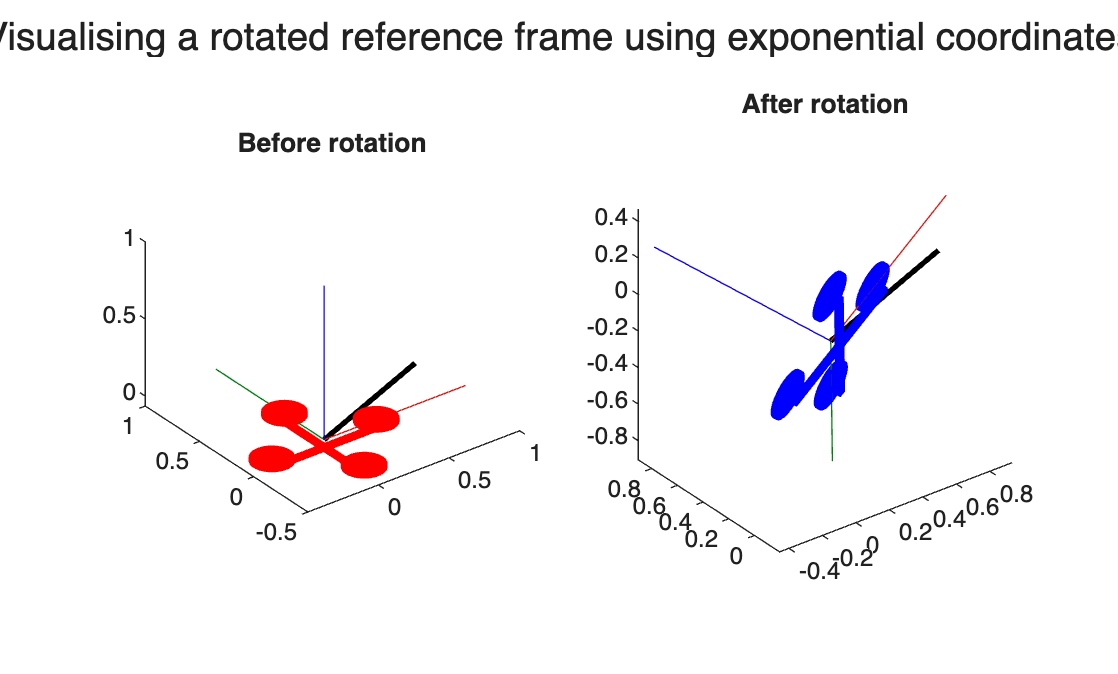

n_x = 1;    %x component of rotation vector
n_y = 0.4;    %y component of rotation vector
n_z = 0;    %z component of rotation vector
n = [n_x n_y n_z]'; 
n = n/norm(n);  %normalised rotation vector

alpha = -70*pi/180;    %rotation angle

S = [0   -n_z  n_y;    %skew-symmetric form of rotation vector
     n_z  0   -n_x;
    -n_y  n_x  0];

% R = expm(S*alpha);
R = eye(3)+sin(alpha)*S+( 1-cos(alpha) )*S^2;    %Rodrigues' formula to determine R

%plot figures
figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'multirotor.stl',"MeshColor","red")
line([0 n(1)],[0,n(2)],[0,n(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation')

subplot(1,2,2)
plotTransforms([0 0 0],rotm2quat(R),"MeshFilePath",'multirotor.stl',"MeshColor","blue")
line([0 n(1)],[0,n(2)],[0,n(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation') 

sgtitle('Visualising a rotated reference frame using exponential coordinates')

Note that when dealing with exponential coordinates in SO(2), the exponential coordinates collapses to $\alpha=\theta$, where $\theta$ corresponds to the rotation experienced by one frame with respect to another whilst bound to a plane.

#### Example: Using Rodrigues' formula

Determine the pose of $\{B\}$ with respect to $\{W\}$ when a frame initially aligned with $\{W\}$ experiences a rotation about ${^W\hat{\bf n}}=[0~0.866~0.5]^T$ with an angle of $\alpha=30^\circ=0.524$ rad.

Using Rodrigues' formula, we obtain


$$\begin{array}{ll}
{^W{\bf R}_B}
&=\mathrm{e}^{\lfloor ^W\hat{\bf n} \rfloor\alpha},\\
&=I+\sin\alpha\lfloor ^W\hat{\bf n} \rfloor +\left(1-\cos\alpha\right)\lfloor ^W\hat{\bf n} \rfloor^2,\\
&=I+0.5\left[\begin{array}{cccccccc}    0 & -0.5 & 0.866 \\    0.5 & 0 & 0 \\    -0.866 & 0 & 0    \\ \end{array}\right]+0.134\left[\begin{array}{cccccccc}    0 & -0.5 & 0.866 \\    0.5 & 0 & 0 \\    -0.866 & 0 & 0    \\ \end{array}\right]^2,\\
&= \left[\begin{array}{cccccccc}    0.866 & -0.250 & 0.433 \\    0.250 & 0.967 & 0.058 \\    -0.433 & 0.058 & 0.899    \\ \end{array}\right].
\end{array}$$


n = [0 0.866 0.5]';    %rotation vector from text above
alpha = 30*pi/180;     %rotation angle from text above

S = [0 -n(3) n(2);    %skew-symmetric form of rotation vector
     n(3) 0 -n(1);
     -n(2) n(1) 0];

R = expm(S*alpha)    %rotation matrix determined from matrix exponential

R =     0.8660   -0.2500    0.4330
    0.2500    0.9665    0.0580
   -0.4330    0.0580    0.8995


R_ = eye(3)+sin(alpha)*S+( 1-cos(alpha) )*S^2    %rotation matrix determined using Rodrigues' formula

R_ =     0.8660   -0.2500    0.4330
    0.2500    0.9665    0.0580
   -0.4330    0.0580    0.8995


### 3.4.3 Principal axis rotations

Recalling that our rotation matrix can be parameterised by the axis-angle representation as


$${\bf R}= \left[\begin{array}{cccccccc}    \mathrm{c}_\alpha+\hat{n}_x^2(1-\mathrm{c_\alpha}) & \hat{n}_x\hat{n}_y(1-\mathrm{c}_\alpha)-\hat{n}_z\mathrm{s}_\alpha & \hat{n}_x\hat{n}_z(1-\mathrm{c}_\alpha)+\hat{n}_y\mathrm{s}_\alpha \\    \hat{n}_x\hat{n}_y(1-\mathrm{c}_\alpha)+\hat{n}_z\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{n}_y^2(1-\mathrm{c_\alpha}) & \hat{n}_y\hat{n}_z(1-\mathrm{c}_\alpha)-\hat{n}_x\mathrm{s}_\alpha  \\    \hat{n}_x\hat{n}_z(1-\mathrm{c}_\alpha)-\hat{n}_y\mathrm{s}_\alpha & \hat{n}_y\hat{n}_z(1-\mathrm{c}_\alpha)+\hat{n}_x\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{n}_z^2(1-\mathrm{c_\alpha})    \\ \end{array}\right],$$


we can easily form the three principal axis rotations of:

- ${\bf R}_x={\bf R}(\alpha,\hat{\bf x})$ — rotation of $\alpha$ about $x$ axis,

- ${\bf R}_y={\bf R}(\alpha,\hat{\bf y})$ — rotation of $\alpha$ about $y$ axis,

- ${\bf R}_z={\bf R}(\alpha,\hat{\bf z})$ — rotation of $\alpha$ about $z$ axis,

by adjusting the components of $\hat{\bf n}=[n_x ~n_y~n_z]^T$ in the rotation matrix equation above.

Specifically, if we set $\hat{\bf n}=[1 ~0~0]^T$ in the rotation matrix equation above, we obtain


$$\begin{array}{cc}{\mathbf R}_x = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\alpha} & -\sin{\alpha \\    0 & \sin{\alpha} & \cos{\alpha}    \\ \end{array}\right],\\ \end{array}$$


if we set $\hat{\bf n}=[0 ~1~0]^T$ we obtain


$$\begin{array}{cc}{\mathbf R}_y = \left[\begin{array}{cccccccc}    \cos{\alpha} & 0 & \sin{\alpha} \\    0 & 1 & 0 \\    -\sin{\alpha} & 0 & \cos{\alpha}    \\ \end{array}\right],\\ \end{array}$$


and if we set $\hat{\bf n}=[0 ~0~1]^T$ we get


$$\begin{array}{cc}{\mathbf R}_z = \left[\begin{array}{cccccccc}    \cos{ \alpha} & -\sin{ \alpha} & 0 \\    \sin{ \alpha } & \cos{ \alpha } & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


These results match of the Euler angle formulation supplied in Section 3.2.1.

### 3.4.4 Matrix logarithms of rotations

We can recover the exponential coordinates, $\alpha\hat{\bf n}$ from a rotation matrix ${\bf R}$ using a **matrix logarithm **operation, which is the *inverse* of the matrix exponential. Specifically, if the rotation matrix is given by


$${\bf R}=\mathrm{\bf e}^{\lfloor \alpha\hat{\bf n} \rfloor}=\mathrm{\bf e}^{\lfloor \hat{\bf n} \rfloor\alpha},$$


then the matrix logarithm of the rotation matrix yields


$$\log{\bf R}= {\lfloor \hat{\bf n} \rfloor\alpha}.$$


Based on this, we can think of the matrix exponential as in *integration operator *for the exponential coordinates, and the matrix logarithm as a *differentiation operator*.

#### Example: Matrix logarithm

Using MATLAB, determine the rotation matrix corresponding to $\hat{\bf n}=[0~~0.866~~0.6]^T$ and $\alpha=30^\circ$, and show that the exponential coordinates can be recovered using the matrix logarithm.

n = [0 0.866 0.5]'    %rotation vector

n =          0
    0.8660
    0.5000


alpha = 30*pi/180     %rotation angle

alpha = 0.5236


S = [0 -n(3) n(2);    %skew-symmetric form of rotation vector
     n(3) 0 -n(1);
     -n(2) n(1) 0];

R = expm(S*alpha);    %rotation matrix from matrix exponential

S_ = logm(R);         %matrix logarithm of rotation matrix
va = [-S_(2,3) S_(1,3) -S_(1,2)]';    %recovered exponential coordinates
alpha_ = norm( va )   %recovered rotation angle

alpha_ = 0.5236

v_ = va/alpha         %recovered rotation vector

v_ =     0.0000
    0.8660
    0.5000


Instead of having to use the matrix logarithm, which is computationally heavy on embedded systems, an algorithm exists that can determine the exponential coordinates. The rotation angle can be determined from the rotation matrix using


$$\alpha=\cos^{-1}\left(\frac{\mathrm{tr}{\bf R}-1}{2}\right),$$


where $\mathrm{tr}{\bf R}$ corresponds to the trace of matrix ${\bf R}$, namely, summing the diagonal entries of ${\bf R}$:

$\mathrm{tr}{\bf R}=r_{11}+r_{22}+r_{33}$.

For $\alpha\neq \pi$, the rotation vector (in skew-symmetric form) is then determined by


$$\lfloor \hat{\bf n} \rfloor = \frac{1}{2\sin{\alpha}}\left({\bf R}-{\bf R}^T\right).$$


For the special case of $\alpha=\pi$, the rotation vector is one of the following solutions, which would need to be verified using ${\bf R}=\mathrm{e}^{\lfloor \hat{\bf n} \rfloor\alpha}=I+\sin\alpha\lfloor \hat{\bf n} \rfloor +\left(1-\cos\alpha\right)\lfloor \hat{\bf n} \rfloor^2$:


$$\hat{\bf n}=\frac{1}{\sqrt{2(1+r_{33})}}\left[\begin{array}{cc}    r_{13} \\   r_{23} \\    1+r_{33}    \\ \end{array}\right], \qquad \hat{\bf n}=\frac{1}{\sqrt{2(1+r_{22})}}\left[\begin{array}{cc}    r_{12} \\   1+r_{22} \\    r_{32}    \\ \end{array}\right]
, \qquad \hat{\bf n}=\frac{1}{\sqrt{2(1+r_{11})}}\left[\begin{array}{cc}    1+r_{11} \\   r_{21} \\    r_{31}    \\ \end{array}\right].$$


### 3.4.5 The dot product and cross product

Recall that the cross product of two unitary vectors is described by


$$\hat{\bf a}\times \hat{\bf b}=\sin{\alpha} \hat{\bf n},$$


where $\alpha$ describes the angle between vectors $\hat{\bf a}$ and $\hat{\bf b}$, and $\hat{\bf n}$ defines the vector perpendicular to $\hat{\bf a}$ and $\hat{\bf b}$. Based on this description, if we were to rotate vector $\hat{\bf a}$ about vector $\hat{\bf n}$ with a rotation of $\alpha$ units, we would obtain $\hat{\bf b}$, namely


$$\begin{array}{ll}
\hat{\bf b}
&={\bf R}\hat{\bf a},\\
&={\bf e}^{\lfloor\alpha\hat{\bf n}\rfloor}\hat{\bf a}.\\
\end{array}$$


As such, $\alpha\hat{\bf n}$ can be thought of as exponential coordinates describing the mapping from $\hat{\bf a}$ and $\hat{\bf b}$. This relationship is useful when dealing with multivariable control design (e.g. thrust vectoring control) and state estimation (comparing vector directions) — both of which will be explored later in this course. Note that when $\alpha$ is sufficiently small, the exponential coordinates can be suitably approximated by $\hat{\bf a}\times \hat{\bf b}=\sin{\alpha} \hat{\bf n}\approx {\alpha} \hat{\bf n}$.

Recall the dot product of two unitary vectors:


$${\hat{\bf a}}\cdot {\hat{\bf b}}=\cos\alpha.$$


Given known $\hat{\bf a}$ and $\hat{\bf b}$, the rotation angle can be recovered by


$$\begin{array}{ll}
\alpha 
&= \cos^{-1}\left({\hat{\bf a}}\cdot {\hat{\bf b}}\right), 
\end{array}$$


where $\alpha \in [0,\pi]$. The rotation vector is then determined by


$${\hat{\bf n}}=\frac{1}{\sin\alpha}\hat{\bf a}\times \hat{\bf b}.

$$


Note that the inverse cosine function will return a value of $\alpha$ between $0$-$\pi$. Additionally, if $\hat{\bf a}$ and $\hat{\bf b}$ are anti-parallel, determination of $\hat{\bf n}$ using the equation above will be incorrect, as  $\hat{\bf a}\times \hat{\bf b}={\bf 0}$ and $\alpha=\pi$. Specifically, when vectors $\hat{\bf a}$ and $\hat{\bf b}$ are collinear (form a line), any rotation vector and rotation angle $\alpha=\pi$ will map $\hat{\bf a}$ to $\hat{\bf b}$. In this case, one could arbitrarily choose a vector that lies in the plane orthogonal to this line.

#### Example: Cross product and rotation matrix

a = [1 2 3]';        %arbitrary vector a
a = a/norm(a);        %arbitrary normalised vector a
b = [-1 1 3]';        %arbitrary vector b
b = b/norm(b)        %arbitrary normalised vector b

b =    -0.3015
    0.3015
    0.9045



n = cross(a,b);    %cross product of vectors a and b
alpha = acos( dot(a,b));    %rotation angle between a and b
c = n/sin(alpha);    %rotation vector perpendicular to a and b

phi = alpha*c;    %exponential coordinates
S = [0 -phi(3) phi(2);    %skew-symmetric form of exponential coordinates
    phi(3) 0 -phi(1);
    -phi(2) phi(1) 0];

R = expm(S);    %rotation matrix
b_ = R*a        %determining vector b using rotation matrix 

b_ =    -0.3015
    0.3015
    0.9045


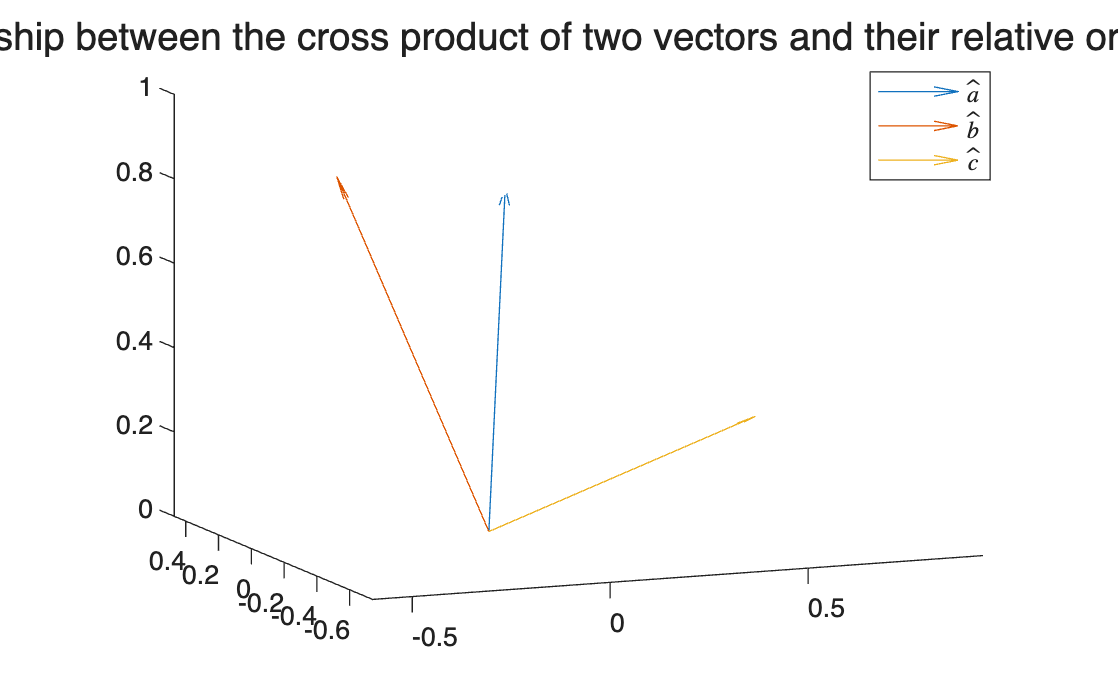


%plot figures
figure, hold on
quiver3(0,0,0,a(1),a(2),a(3))
quiver3(0,0,0,b(1),b(2),b(3))
quiver3(0,0,0,c(1),c(2),c(3))
legend('$\hat{a}$','$\hat{b}$','$\hat{c}$','Interpreter','Latex')
axis equal
sgtitle('Relationship between the cross product of two vectors and their relative orientation')

%set x-y axis limits and view angle
xlim([-0.60 0.94])
ylim([-0.74 0.47])
view([-22.493 9.992])

## 3.5 Angular velocity

Angular velocity will dictate how our orientation changes over time, so we are therefore interested in how the two are related when dealing with multiple reference frames. This is important when mathematically modelling systems (for example when designing simulation environments) and also when angular rate information is available from a sensor (for example a gyroscope) and we want to estimate orientation from it. 

In the case of planar rotations (resulting in rotations about a fixed principle axis) the relationship is trivial, but we require more scrutiny for the generalised spatial case when up to three degrees of rotation freedom are at work.

### 3.5.1 Rotation matrix derivative

To understand the relationship between angular velocity and orientation, we need to develop a better understanding of reference frame motion as they rotate. Consider the motion of a point fixed to the end of ${^W\hat{\bf x}_B$ when $\{B\}$ experiences and angular velocity of ${^W{\bf \omega}}$, as shown in Figure 3.5.

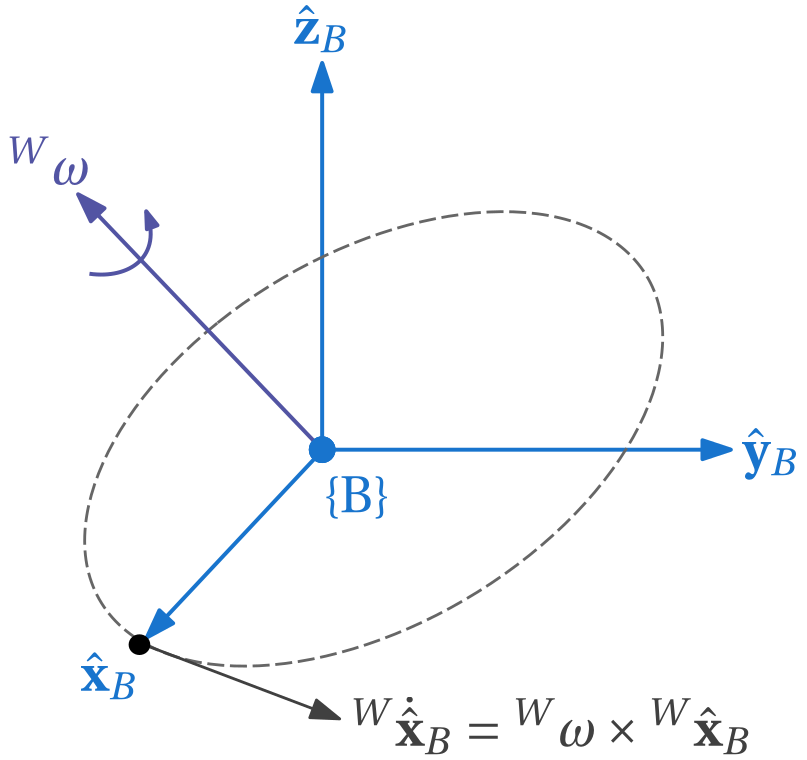

**Figure 3.5:** Reference frame $\{B\}$ experiencing angular velocity. ${^W\hat{\bf x}_B$ experiences translational velocity based on angular velocity ${^W{\bf\omega}}$.

Recall that ${^W\hat{\bf x}_B$ describes the $x$-axis of the body frame when described in the world frame, which is obtained by


$$\begin{array}{ll}
{^W\hat{\bf x}_B
&={^W{\bf R}_B\hat{\bf x}_B,\\
&={^W{\bf R}_B\left[\begin{array}{cccccccc}    1 \\    0 \\   0    \\ \end{array}\right].\\
\end{array}$$


Given the orthogonality property of ${^W{\bf R}_B$, ${^W\hat{\bf x}_B$ will always have unit length. This means that during rotation, only the direction of ${^W\hat{\bf x}_B$ will change — not the length. Given that the angular velocity of the body frame is described in the world frame as ${^W{\bf \omega}}$, we can determine the rate of change of ${^W\hat{\bf x}_B$ based on elementary mechanics, namely

${^W\dot{\hat{\bf x}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf x}}_B}$.

We can repeat this process for the other two axes of $\{B\}$without loss of generality, which yields 

${^W\dot{\hat{\bf y}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf y}}_B}$.

${^W\dot{\hat{\bf z}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf z}}_B}$.

Recalling that


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right],\ \end{array}$$


the derivative of the rotation matrix follows as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    ^W\dot{\hat{\mathbf x}}_B & ^W\dot{\hat{\mathbf y}}_B & ^W\dot{\hat{\mathbf z}}_B    
\end{array}\right],\\
&=     \left[\begin{array}{cccc}    {^W{\bf\omega}}\times {^W\hat{\bf x}_B} & {^W\bf\omega}\times {^W\hat{\bf y}_B} & {^W{\bf\omega}}\times {^W\hat{\bf z}_B}\\
\end{array}\right].\\


\end{array}$$


Making use of our skew-symmetric form for the cross product, namely


$$\begin{array}{cc}
{{\bf \omega} \times {\bf r} = 
\lfloor {\mathbf\omega} \rfloor {\bf r}, \end{array}$$


we can express the rotation matrix derivative as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    {^W{\bf\omega}}\times {^W\hat{\bf x}_B} & {^W\bf\omega}\times {^W\hat{\bf y}_B} & {^W{\bf\omega}}\times {^W\hat{\bf z}_B}\\
\end{array}\right],\\
& = \lfloor {^W\mathbf\omega} \rfloor \left[\begin{array}{cccc}     {^W\hat{\bf x}_B} &  {^W\hat{\bf y}_B} &  {^W\hat{\bf z}_B}\\
\end{array}\right],\\
& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B}.

\end{array}$$


This result is quite interesting, as it suggests that the rate of change of our orientation encoder will be a function of both the angular velocity vector and current orientation. It can be shown that for any ${\bf R}\in$ SO(3) and $\bf \omega\in \mathbb{R}^3$,


$$\begin{array}{cc}\lfloor {\mathbf R}{\mathbf\omega} \rfloor = {\mathbf R}\lfloor {\mathbf\omega} \rfloor {\mathbf R}^T. \end{array}$$


Recalling that we can relate the angular velocity between different frames using


$$\begin{array}{cc}{^W\mathbf\omega} = {^W{\mathbf R}_B} {^B\mathbf\omega}, \end{array}$$


and this, along with the result above of $\begin{array}{cc}\lfloor {\mathbf R}{\mathbf\omega} \rfloor = {\mathbf R}\lfloor {\mathbf\omega} \rfloor {\mathbf R}^T \end{array}$ can be used to determine the rotation matrix derivative as a function of ${^B\mathbf\omega}$:


$$\begin{array}{ll}^W\dot{\mathbf R}_B 

& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B},\\
& = \lfloor {{^W{\mathbf R}_B}^B\mathbf\omega} \rfloor  {^W{\mathbf R}_B},\\
& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  {^W{\mathbf R}^T_B}{^W{\mathbf R}_B},\\
& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  .
\end{array}$$


Note the similarity when determining $\begin{array}{ll}^W\dot{\mathbf R}_B 



\end{array}$ as a function of $^W{\bf \omega}$ and $^B{\bf \omega}$. 

### 3.5.2 Quaternion derivative

The relationship between angular velocity and the quaternion follows a similar pattern to that of the rotation matrix counterpart. The full derivation will be spared here for sake of time. Analogous to the result of $\begin{array}{ll}^W\dot{\mathbf R}_B 

& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B}

\end{array}$, the quaternion derivative can be written as 


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W\mathbf\Omega}\otimes{^W{\mathbf q}_B},\end{array}$$


where 


$$\begin{array}{ll}
{^W\mathbf\Omega}
&=\left[\begin{array}{cccccccc}    0 \\    ^W{\bf\omega}    \\ \end{array}\right]\\
\end{array}$$


is a "pure" quaternion formed from the angular velocity vector in frame $\{W\}$. Using appropriate identities, the quaternion derivative can be written as 


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W{\mathbf q}_B}\otimes{^B\mathbf\Omega},\end{array}$$


where


$$\begin{array}{ll}
{^B\mathbf\Omega}
&=\left[\begin{array}{cccccccc}    0 \\    ^B{\bf\omega}    \\ \end{array}\right],
\end{array}$$


which follows a similar structure but now using the angular velocity in $\{B\}$. 

## 3.6 Obtaining orientation from angular velocity

If the angular velocity is known exactly, we can use this information to determine the corresponding orientation at a given time using integration. We must, however, take into account the particular reference frame mapping, such as from $\{B\}$ to $\{W\}$ when the velocity is described in $\{B\}$, before performing the integration operation — otherwise the resulting "orientation" described in $\{B\}$ is meaningless in general.

### 3.6.1 Rotation matrix formulation

The incremental orientation can be determined in rotation matrix form using exponential coordinates. Recall that 


$${\bf R}=\mathrm{\bf e}^{\lfloor \alpha\hat{\bf n} \rfloor}=\mathrm{\bf e}^{\lfloor \hat{\bf n} \rfloor\alpha},$$


where $\alpha\hat{\bf n}$ are the exponential coordinates describing a generalised 3D rotation. Assuming a body experiences an angular velocity vector of ${^B{\bf \omega}}$, expressed in $\{B\}$, for a duration of $\Delta t$ units of time, we can determine the incremental exponential coordinates corresponding to rotating about vector ${^B{\bf \omega}}$ for $\Delta t$ units of time (usually seconds) using 


$${^B{\bf \theta}={^B{\bf \omega}}\Delta t.$$


The incremental rotation angle and normalised rotation vector follow respectively as 


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$



$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|}.$$


The corresponding incremental rotation matrix is given by


$$\begin{array}{ll}
\Delta{\bf R}
&=\mathrm{\bf e}^{\lfloor {^B{\bf \theta}} \rfloor},\\
&=\mathrm{\bf e}^{\lfloor {^B{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\alpha\right)\lfloor ^B\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}}|\Delta t)\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B{\bf \omega}}|\Delta t)\right)\lfloor ^B\hat{\bf \omega} \rfloor^2.
\end{array}
$$


If our orientation is originally described as $^W{\bf R}_{\{0\}}$ prior to experiencing the angular velocity, we can then determine our updated orientation, ${^W{\bf R}_{\{1\}}}$, by post-multiplying $^W{\bf R}_{\{0\}}$ by the incremental rotation matrix, namely


$${^W{\bf R}_{\{1\}}}={^W{\bf R}_{\{0\}}}{^{\{0\}}{\bf R}_{\{1\}},$$
 

where $\Delta{\bf R}={^{\{0\}}{\bf R}_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. This process can be repeated any number of times, assuming one is able to capture each incremental rotation matrix that corresponds to the angular velocity that was experienced for the given time frame. This is generalised as


$${^W{\bf R}_{\{n\}}}={^W{\bf R}_{\{0\}}}{^{\{0\}}{\bf R}_{\{1\}} \dots {^{\{n-1\}}{\bf R}_{\{n\}}.$$
 

Note that we are post-multiplying in each instance, as the rotation vector is described in $\{B\}$. If instead we had information of ${^W{\bf \omega}}$, we would need to pre-multiply in each instance.

### 3.6.2 Quaternion formulation

Recall that the quaternion encodes the exponential coordinates. Given our previously defined incremental axis-angle representation from Section 3.6.1 of


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$
        
$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|},$$


we can determine the corresponding incremental quaternion as


$$\begin{array}{cc}\Delta{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\Delta\alpha}{2}} \\ \sin{\frac{\Delta\alpha}{2}} {^B\hat{\mathbf \omega}}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \\     \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_x \\    \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_y \\    \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_z    \\ \end{array}\right].\end{array}$$


If our orientation is originally described by $^W{\bf q}_{\{0\}}$ prior to experiencing the angular velocity, we can then determine our updated orientation, ${^W{\bf q}_{\{1\}}}$, by post-multiplying $^W{\bf q}_{\{0\}}$ by the incremental quaternion, namely


$${^W{\bf q}_{\{1\}}}={^W{\bf q}_{\{0\}}}\otimes{^{\{0\}}{\bf q}_{\{1\}},$$
 

where $\Delta{\bf q}={^{\{0\}}{\bf q}_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. This process can be repeated any number of times, assuming one is able to capture each incremental rotation matrix that corresponds to the angular velocity that was experienced for the given time frame. This is expressed as


$${^W{\bf q}_{\{n\}}}={^W{\bf q}_{\{0\}}}\otimes{^{\{0\}}{\bf q}_{\{1\}}\otimes \dots \otimes{^{\{n-1\}}{\bf q}_{\{n\}}.$$
 

As with the rotation matrix formulation, we are post-multiplying in each instance, as the rotation vector is described in $\{B\}$. If instead we had information of ${^W{\bf \omega}}$, we would need to pre-multiply in each instance.

#### Example: Determining quaternion-based orientation from angular velocity

The code block below provides a simulation of how angular velocity information can be correctly integrated and mapped to obtain a quaternion-based representation of orientation. 

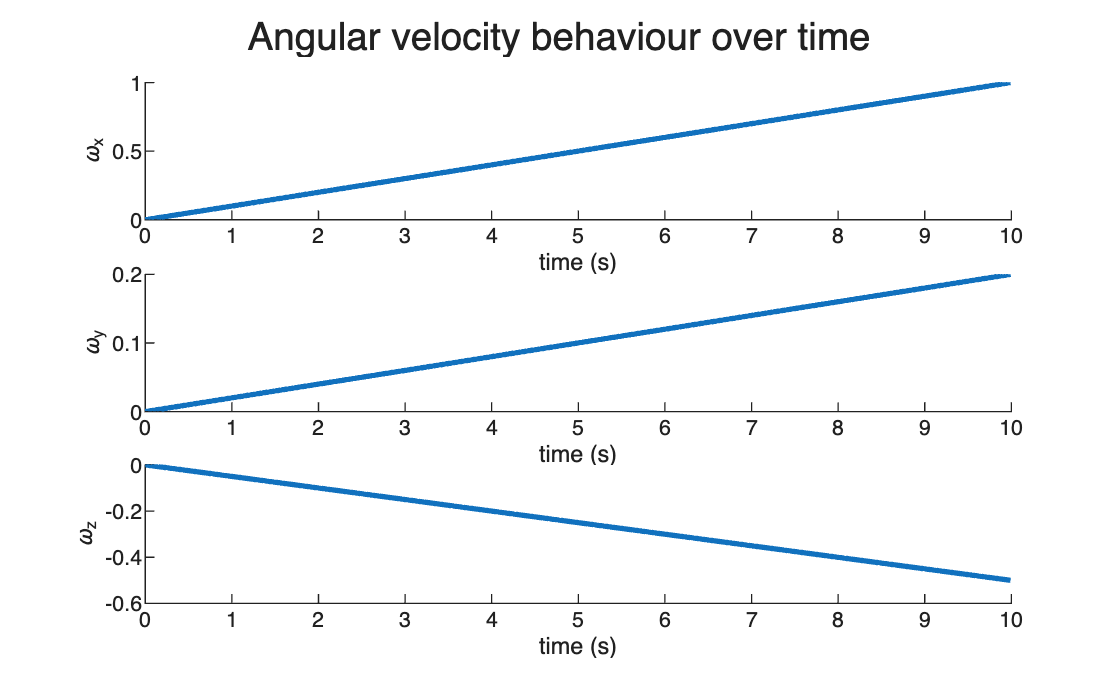

dT = 0.01;  %sampling duration
numSamples = 1000;      %number of samples
t = (0:numSamples-1)*dT;    %time vector

omega1 = linspace(0,1,numSamples);
omega2 = linspace(0,0.2,numSamples);
omega3 = linspace(0,-0.5,numSamples);
omega = [omega1' omega2' omega3'];  %generate arbitrary 3D angular velocity


q = zeros(numSamples,4);    %initialise quaternion array
q(1,1:4) = [1 0 0 0];       %initialise first sample of quaternion to be null quaternion

for k=1:numSamples-1
    %actual
    dtheta = omega(k,:)*dT; %determine incremental exponential coordinates
    dalpha = norm(dtheta);  %determine incremental rotation angle
    if( dalpha == 0)        %determine incremental rotation vector
        n = [0 0 0];
    else
        n = dtheta/dalpha;
    end
    dq = [cos(dalpha) sin(dalpha)*n];   %populate incremental quaternion
    q(k+1,1:4) = quatmultiply(q(k,1:4),dq); %calculate updated quaternion at sample instance k+1
    q(k+1,1:4) = q(k+1,1:4)/norm( q(k+1,1:4) ); %normalise quaternion
end
%plot angular velocity figures
figure, sgtitle('Angular velocity behaviour over time')
subplot(3,1,1),hold on
plot(t,omega(:,1),lineWidth=2),xlabel('time (s)'),ylabel('\omega_x')
subplot(3,1,2),hold on
plot(t,omega(:,2),lineWidth=2),xlabel('time (s)'),ylabel('\omega_y')
subplot(3,1,3),hold on
plot(t,omega(:,3),lineWidth=2),xlabel('time (s)'),ylabel('\omega_z')

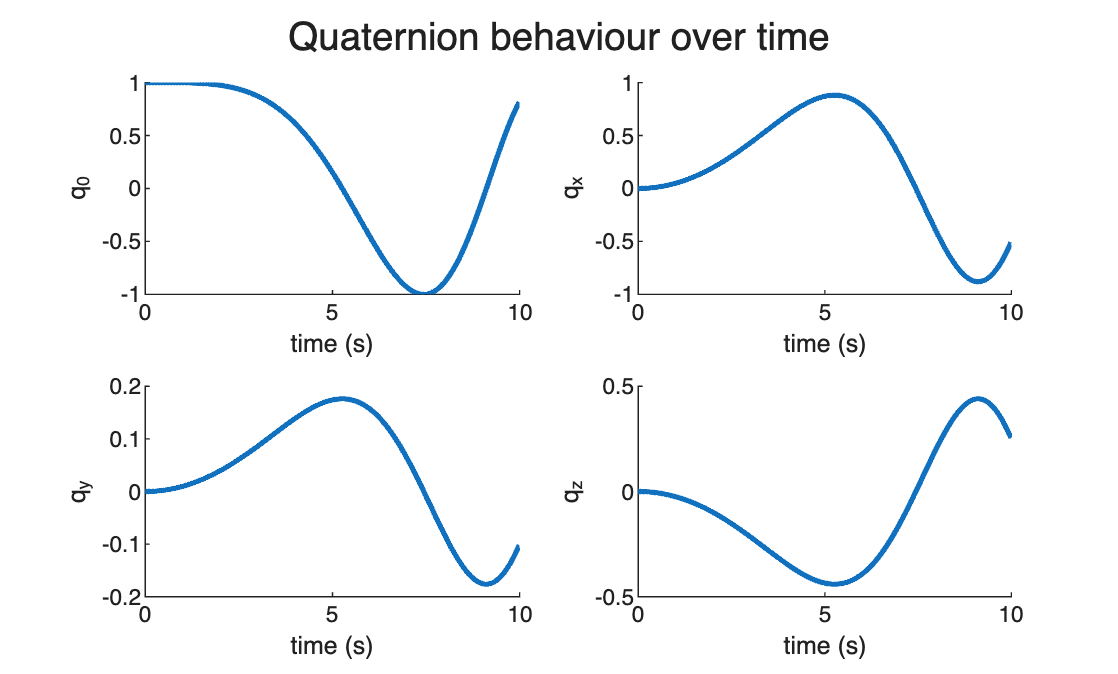



%plot quaternion figures
figure, sgtitle('Quaternion behaviour over time')
subplot(2,2,1),hold on
plot(t,q(:,1),lineWidth=2),xlabel('time (s)'),ylabel('q_0')
subplot(2,2,2),hold on
plot(t,q(:,2),lineWidth=2),xlabel('time (s)'),ylabel('q_x')
subplot(2,2,3),hold on
plot(t,q(:,3),lineWidth=2),xlabel('time (s)'),ylabel('q_y')
subplot(2,2,4),hold on
plot(t,q(:,4),lineWidth=2),xlabel('time (s)'),ylabel('q_z')

## 3.7 Exponential coordinates in SE(3)

### 3.7.1 Definition

Recall that the exponential map is used to map exponential coordinates to rotation matrices using


$${\bf R}=\mathrm{e}^{\lfloor \hat{\bf n} \rfloor\alpha}=I+\sin\alpha\lfloor \hat{\bf n} \rfloor +\left(1-\cos\alpha\right)\lfloor \hat{\bf n} \rfloor^2.$$


Inversely, rotation matrices can be mapped to exponential coordinates in SO(3) using the (matrix) logarithmic mapping, 


$$\log{\bf R}= {\lfloor \hat{\bf n} \rfloor\alpha}.$$


Analogous to how exponential coordinates of rotations can be mapped to/from rotation matrices (or quaternions), there exist exponential coordinates of pose (position and orientation) that can be mapped to transformation matrices. The exponential coordinates in SE(3) are defined as


$$\begin{array}{cc}
{}{\bf \xi}
= \left[\begin{array}{cc}    {\bf\theta} \\ \Delta{\bf  p}    \\ \end{array}\right]
=\left[\begin{array}{cc}    \alpha \hat{\bf n} \\ \Delta{\bf  p}    \\ \end{array}\right],\end{array}$$


where ${\bf\theta}=\alpha\hat{\bf n}$ represents the rotational exponential coordinates, based on Section 3.4, and $\Delta {\bf p}$ describes the translational exponential coordinates, which is the displacement experienced within the vector space. The vector above is often also referred to as the twist vector.

Importantly, this information will have different geometric meanings depending on in which frame it is described in. The tangent space representation of the exponential coordinates in SE(3) is given by


$$\begin{array}{ll}
\lfloor{\bf \xi}\rfloor
&= \left[\begin{array}{cc}    \lfloor{\bf\theta}\rfloor & \Delta{\bf  p} \\ {\bf 0} & 1    \\ \end{array}\right], \\
&= \left[\begin{array}{cc}    \lfloor \alpha \hat{\bf n}\rfloor & \Delta{\bf  p} \\ {\bf 0} & 1    \\ \end{array}\right],
\end{array}$$


which can be thought of as the encoded matrix form of the exponential coordinates. Finally, the transformation matrix describing the pose is obtained by mapping the tangent space representation through the exponential mapping:


$$\begin{array}{ll}
{\bf T}
&={\bf e}^{\lfloor {\bf \xi}\rfloor}\\
&= {\bf e}^{\left[\begin{array}{cc}    \lfloor{\bf\theta}\rfloor & \Delta{\bf  p} \\ {\bf 0} & 1    \\ \end{array}\right]}.
\end{array}$$


### 3.7.2 Left Jacobian of SO(3)

To avoid having to mathematically evaluate the matrix exponential every time we need to evaluate the equation above, we can instead make use of a compact closed form solution. Recall that the exponential mapping in SO(3) is given by


$${\bf R}=\mathrm{e}^{\lfloor \hat{\bf n} \rfloor\alpha}=I+\sin\alpha\lfloor \hat{\bf n} \rfloor +\left(1-\cos\alpha\right)\lfloor \hat{\bf n} \rfloor^2,$$


which provides us a direct means of determining the rotation matrix if we know the rotational exponential coordinates. Analogous to this, the transformation matrix can be determined by


$$\begin{array}{ll}
{\bf T}
&={\bf e}^{\lfloor {\bf \xi}\rfloor},\\
&= {\bf e}^{\left[\begin{array}{cc}    \lfloor{\bf\theta}\rfloor & \Delta{\bf  p} \\ {\bf 0} & 0    \\ \end{array}\right]},\\
&={\left[\begin{array}{cc}    {\bf R} & {\bf V}\Delta{\bf  p} \\ {\bf 0} & 0    \\ \end{array}\right]},
\end{array}$$


where $\bf V$ is known as the left Jacobian of SO(3) and is given by


$${\bf V} = {\bf I} + \frac{{\bf I} - {\bf R}}{\alpha} \lfloor\hat\mathbf{n}\rfloor,$$


and 


$${\bf R}=\mathrm{e}^{\lfloor \hat{\bf n} \rfloor\alpha}=I+\sin\alpha\lfloor \hat{\bf n} \rfloor +\left(1-\cos\alpha\right)\lfloor \hat{\bf n} \rfloor^2.$$


Importantly, matrix $\bf V$ accounts for the fact that the robot is rotating *while* it is translating, creating a curved path rather than a straight line. The combination of Rodrigues' formula and the left Jacobian of SO(3) means that the transformation matrix can be easily determined if one knows the twist vector.

### 3.7.3 Body twist

In order to make use of the exponential coordinates in SE(3) in a meaningful way, we need to be aware of which reference frame is being used to represent the information. In this course we will predominantly base exponential coordinates in SE(3) in $\{B\}$. As such, we can represent the body-frame 6-vector exponential coordinates using


$$\begin{array}{cc}
{^B}{\bf \xi}
= \left[\begin{array}{cc}    ^B{\bf\theta} \\ ^B\Delta{\bf  p}    \\ \end{array}\right]
=\left[\begin{array}{cc}    \alpha ^B\hat{\bf n} \\ ^B\Delta{\bf  p}    \\ \end{array}\right].\end{array}$$


Physically, we can interpret the vector above as describing a rigid body that has simultaneously experienced a rotation of $\alpha$ units about vector $^B\hat{\bf n}$ and a displacement of the body-frame origin of $^B{\Delta {\bf p}}$ units. 

The usefulness of this formulation is that if the robot has some initial pose represented by ${^W{\bf T}_{B_0}$, and then subsequently experiences incremental motion as described in the equation above, we can then (exactly) update the pose representation of our robot using


$${^W{\bf T}_{B}={^W{\bf T}_{B_0}{\bf e}^{\lfloor ^{B_0}{\bf \xi}\rfloor}.$$


Note that this approach is analogous to how we incrementally updated the rotation matrix as shown in Section 3.6.1.

Kinematically, the exponential coordinates are derived by obtaining the body-frame velocity information and then integrating the (assumed) constant velocity over the particular time frame. The 6-vector describing the body-frame velocity is commonly known as the **body twist **and is given by


$$\begin{array}{cc}
{^B}{\mathcal{V}}
= \left[\begin{array}{cc}    ^B{\bf\omega} \\ ^B{\bf  v}    \\ \end{array}\right]
,\end{array}$$


where $^B{\bf\omega}$ is the body-frame angular velocity of the rigid body, and $^B{\bf v}$ is the body-frame translational velocity. The body twist can then by related to the exponential coordinates in SE(3) using


$$\begin{array}{cc}
{^B}{\bf \xi} = 
{^B}{\mathcal{V}}\Delta t= \left[\begin{array}{cc}    ^B{\bf\omega} \\ ^B{\bf  v}    \\ \end{array}\right]\Delta t
,\end{array}$$


where $\Delta t$ is the duration of time in which the body twist was experienced.

#### Example: Transformation matrix from body twist

Using MATLAB, determine the transformation matrix representing the pose of $\{B\}$ with respect to $\{W\}$ when a rigid body initial aligned with $\{W\}$ experiences a translational velocity of $^B{\bf v}$ and a rotational velocity of $^B{\bf \omega}$ over a one second period.

vx = 0;
vy = 0;
vz = 0;
v = [vx vy vz]'; %body translational velocity vector

wx = -1;
wy = 0;
wz = 0;
w = [wx wy wz]'; %body rotational velocity vector

dT = 1; %sample time
twist = [w; v]; %body twist
expCoords = twist*dT; %exponential coordinates

S = [0           -expCoords(3)  expCoords(2) expCoords(4);    %tangent space representation of exponential coordinates
     expCoords(3) 0            -expCoords(1) expCoords(5);
    -expCoords(2) expCoords(1)  0            expCoords(6)
     0             0            0            0];

T = expm(S)

T =     1.0000         0         0         0
         0    0.5403    0.8415         0
         0   -0.8415    0.5403         0
         0         0         0    1.0000


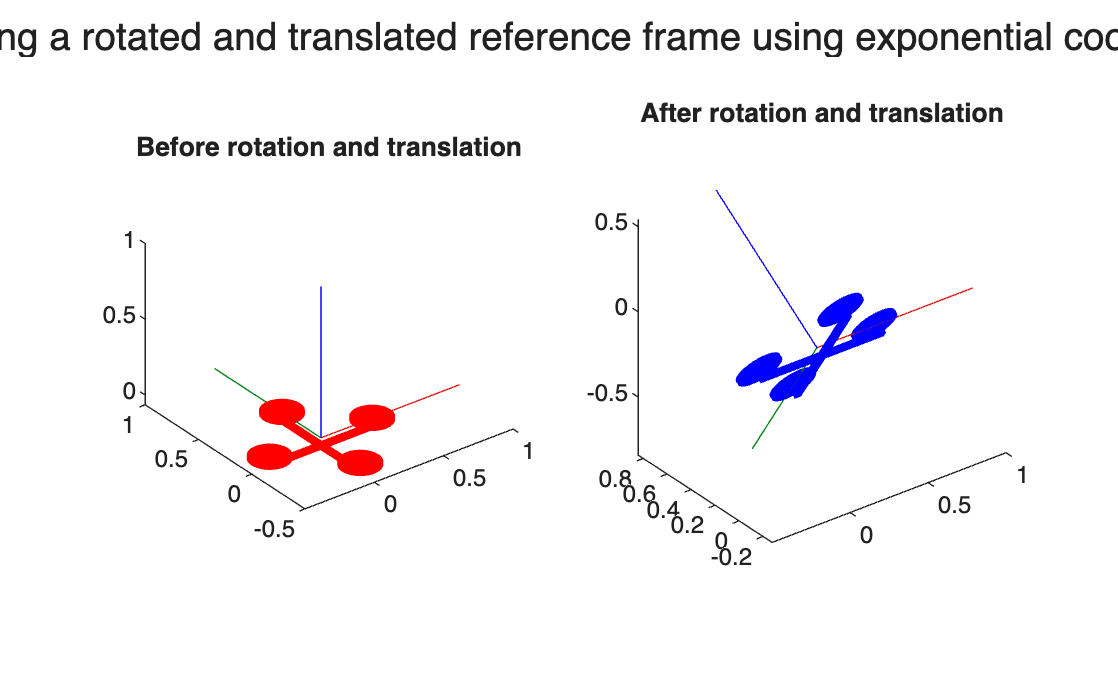


%plot figures
figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'multirotor.stl',"MeshColor","red")
axis equal,title('Before rotation and translation')

subplot(1,2,2)
plotTransforms(tform2trvec(T),tform2quat(T),"MeshFilePath",'multirotor.stl',"MeshColor","blue")
axis equal,title('After rotation and translation') 

sgtitle('Visualising a rotated and translated reference frame using exponential coordinates')